# Fast cyclic dorsiflexion test - group analyses

Author: P Valadao pvaladao@tuta.io.

Last modified: 07/04/22.

Each subject received 40 stretches at 4 velocities (50, 100, 200, 300 deg/s). Whenever no stretch reflex happened, the dynamic stretch reflex threshold (DSRT) was set to zero. 

Stretch reflex burst (50 ms) is beeing normalized with the highest slidding 200ms RMS MVC window of each participant.

## Data Preparation

Add_info: remove subjects without data in fast dorsiflexion test, remove unnecessary vars from the table,  merge table into TSRT_main so that max mvc rms values are available for stretch reflex burst normalization. 

TSRT_main: Remove Invalid trials (pre-stretch EMG RMS > 5%MVC EMG RMS and trials without SRs). Create 2 tables separating muscles because there are different n of DSRT and tables require the same amount of rows for all vars. TSRT_main has all raw datapoints, Merged_all has medians for all vars (velocities are pooled). 

load add_info.mat
add_info = removevars(add_info,{'Group','Test','Sol_lat','MG_lat'}); %remove unwanted vars
add_info = add_info(add_info.Subject ~= "5102" & add_info.Subject ~= "5113" ...
   & add_info.Subject ~= "5209",:);
%remove subjects that do not have TSRT data from the add.info table
load Fast_cyclic_DF_all.mat
TSRT_main_all = outerjoin(TSRT_main_all,add_info,'Keys',{'Subject'},'MergeKeys',true);
TSRT_main_all.EMG_normalized_sol = TSRT_main_all.Onset_emg_Sol./TSRT_main_all.max_peak_emgrms_sol_200;% emg burst RMS/MVC RMS
TSRT_main_all.EMG_normalized_mg = TSRT_main_all.Onset_emg_MG./TSRT_main_all.max_peak_emgrms_mg_200;
TSRT_main_all.Group = categorical(TSRT_main_all.Group);% make group a categorical var
TSRT_main_all.Velocity_round = TSRT_main_all.Velocity; % new var for rounded velocity to allow settting as categorical
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round <75) = 50;
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round > 75 & TSRT_main_all.Velocity_round < 140 ) = 100;
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round > 140 & TSRT_main_all.Velocity_round < 230 ) = 200;
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round > 230) = 300;
TSRT_main_all.Velocity_round = categorical(TSRT_main_all.Velocity_round);
TSRT_main = TSRT_main_all(TSRT_main_all.Subject ~= "5105",:); % exclude case study (5105)
TSRT_main = TSRT_main(TSRT_main.cond_mvc_sol == 1 & TSRT_main.cond_mvc_mg == 1,:);%remove invalid trials (mvc_cond == 0)
TSRT_Sol = TSRT_main(:,{'Subject','Group','Trial','Velocity','DSRT_Sol','DSRT_Sol_Lat','Onset_emg_Sol','Velocity_round', ...
    'EMG_normalized_sol'}); %separate vars of interrest for sol
TSRT_Sol = TSRT_Sol(TSRT_Sol.DSRT_Sol_Lat ~=0,:); %remove trials without DRST for soleus
TSRT_MG = TSRT_main(:,{'Subject','Group','Trial','Velocity','DSRT_MG','DSRT_MG_Lat','Onset_emg_MG','Velocity_round', ...
    'EMG_normalized_mg'}); %separate vars of interrest for mg
TSRT_MG = TSRT_MG(TSRT_MG.DSRT_MG_Lat ~=0,:);%remove trials without DRST for mg
%save ('muscle_data.mat','TSRT_Sol', 'TSRT_MG')
load merged_data_all.mat
Merged = merged_all(merged_all.Subject ~= "5105",:);%remove case study from merged data
clear TSRT_main_all  merged_all

## Stretch Reflex Threshold

### Soleus Stretch reflex onset - two highest velocities pooled / medians of participants.

5102/5113/5209 had bad EMG. 5208/5202 had no SR at the 2 highest velocities.

CP data is not normally distributed, groups have equal variances. Wilcoxon rank sum test was utilized. 13 CP, 12 TD.

CP_sol_median_dsrt_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "200" | ...
    TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "300",:),"Subject",'median','DSRT_Sol_Lat');
TD_sol_median_dsrt_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "TD" & TSRT_Sol.Velocity_round == "200" | ...
     TSRT_Sol.Group == "TD" & TSRT_Sol.Velocity_round == "300",:),"Subject",'median','DSRT_Sol_Lat');
CP_total_dsrt_sol = sum(table2array(CP_sol_median_dsrt_descriptives(:,2)))

CP_total_dsrt_sol = 179

TD_total_dsrt_sol = sum(table2array(TD_sol_median_dsrt_descriptives(:,2)))

TD_total_dsrt_sol = 92

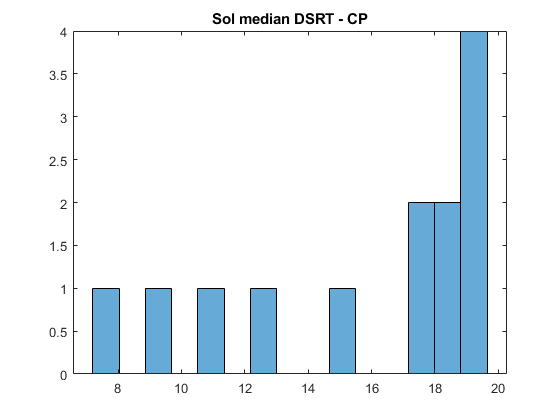

CP_sol_median_dsrt = table2array(CP_sol_median_dsrt_descriptives(:,3)); %only dsrt values, no subject code and groupcount
TD_sol_median_dsrt = table2array(TD_sol_median_dsrt_descriptives(:,3));
histogram(CP_sol_median_dsrt,15),title('Sol median DSRT - CP'),

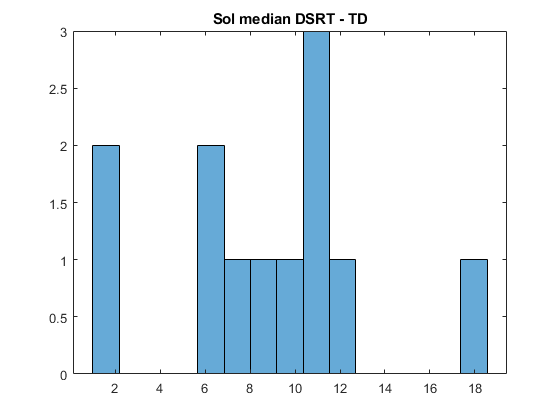

histogram(TD_sol_median_dsrt,15), title('Sol median DSRT - TD'),

kurtosis_CP = kurtosis(CP_sol_median_dsrt)

kurtosis_CP = 2.2757

kurtosis_TD = kurtosis(TD_sol_median_dsrt)

kurtosis_TD = 3.0239

skewness_CP = skewness(CP_sol_median_dsrt)

skewness_CP = -0.8942

skewness_TD = skewness(TD_sol_median_dsrt)

skewness_TD = 0.2820

normalitytest(CP_sol_median_dsrt'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.0140 	     0.2553                 1 
KS Stephens Modification       1.0775 	     0.0100                 0 
KS Marsaglia Method            1.0140 	     0.2110                 1 
KS Lilliefors Modification     0.2812 	     0.0059                 0 
Anderson-Darling Test          1.1198 	     0.0073                 0 
Cramer- Von Mises Test         0.1994 	     0.0055                 0 
Shapiro-Wilk Test              0.8167 	     0.0108                 0 
Shapiro-Francia Test           0.8289 	     0.0166                 0 
Jarque-Bera Test               2.0168 	     0.3648                 1 
DAgostino & Pearson Test       2.7970 	     0.2470                 1 


normalitytest(TD_sol_median_dsrt');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6021 	     0.8615                 1 
KS Stephens Modification       0.6430 	     0.1500                 1 
KS Marsaglia Method            0.6021 	     0.8033                 1 
KS Lilliefors Modification     0.1738 	     0.2000                 1 
Anderson-Darling Test          0.3519 	     0.4682                 1 
Cramer- Von Mises Test         0.0465 	     0.5635                 1 
Shapiro-Wilk Test              0.9420 	     0.5240                 1 
Shapiro-Francia Test           0.9350 	     0.3662                 1 
Jarque-Bera Test               0.1593 	     0.9234                 1 
DAgostino & Pearson Test       0.9293 	     0.6284                 1 


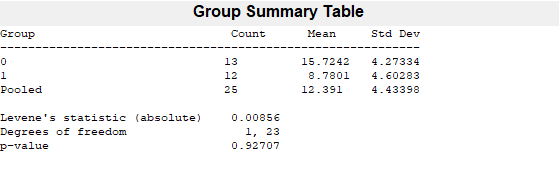

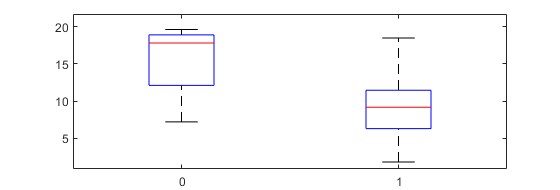

p = 0.9271

group_sol_dsrt = CP_sol_median_dsrt; %create matrix with dsrt + group for vartestn test
group_sol_dsrt(:,2) = 0;
group_sol_dsrt(end+1:end+length(TD_sol_median_dsrt),1) = TD_sol_median_dsrt;
group_sol_dsrt(14:end,2) = 1;
p = vartestn(group_sol_dsrt(:,1),group_sol_dsrt(:,2),'TestType','LeveneAbsolute')

p = vartestn(group_sol_dsrt(:,1),group_sol_dsrt(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.7966

[p,h,stats] = ranksum(CP_sol_median_dsrt,TD_sol_median_dsrt) %Wilcoxon rank sum test

p = 0.0021

h = logical
   1

stats = struct with fields:
       zval: 3.0732
    ranksum: 226

median(CP_sol_median_dsrt)

ans = 17.8024

iqr(CP_sol_median_dsrt)

ans = 6.7815

median(TD_sol_median_dsrt)

ans = 9.1666

iqr(TD_sol_median_dsrt)

ans = 5.1686

### MG Stretch reflex onset - two highest velocities pooled / medians of participants.

CP is not normally distributted, groups have equal variances. 5218/5217 had no SR. 5102/5113/5209 had bad emg. 13 CP vs. 12 TD.

CP_mg_median_dsrt_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "200" |...
    TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "300",:),"Subject",'median','DSRT_MG_Lat');
TD_mg_median_dsrt_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "TD" & TSRT_MG.Velocity_round == "200" |...
    TSRT_MG.Group == "TD" & TSRT_MG.Velocity_round == "300",:),"Subject",'median','DSRT_MG_Lat');
CP_total_dsrt_mg = sum(table2array(CP_mg_median_dsrt_descriptives(:,2)))

CP_total_dsrt_mg = 170

TD_total_dsrt_mg = sum(table2array(TD_mg_median_dsrt_descriptives(:,2)))

TD_total_dsrt_mg = 84

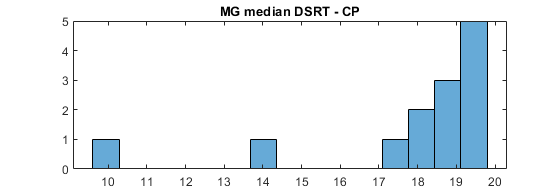

CP_mg_median_dsrt = table2array(CP_mg_median_dsrt_descriptives(:,3)); %only dsrt values, no subject code and count
TD_mg_median_dsrt = table2array(TD_mg_median_dsrt_descriptives(:,3));
histogram(CP_mg_median_dsrt,15),title('MG median DSRT - CP'),

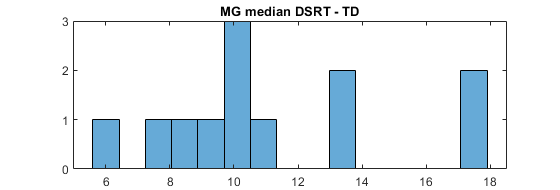

histogram(TD_mg_median_dsrt,15), title('MG median DSRT - TD'),

kurtosis_CP = kurtosis(CP_mg_median_dsrt)

kurtosis_CP = 6.0825

kurtosis_TD = kurtosis(TD_mg_median_dsrt)

kurtosis_TD = 2.4374

skewness_CP = skewness(CP_mg_median_dsrt)

skewness_CP = -2.0288

skewness_TD = skewness(TD_mg_median_dsrt)

skewness_TD = 0.6666

normalitytest(CP_mg_median_dsrt'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.2000 	     0.1123                 1 
KS Stephens Modification       1.2751 	     0.0100                 0 
KS Marsaglia Method            1.2000 	     0.0874                 1 
KS Lilliefors Modification     0.3328 	     0.0003                 0 
Anderson-Darling Test          1.7401 	     0.0005                 0 
Cramer- Von Mises Test         0.3135 	     0.0002                 0 
Shapiro-Wilk Test              0.6882 	     0.0004                 0 
Shapiro-Francia Test           0.6713 	     0.0005                 0 
Jarque-Bera Test               14.0650 	     0.0009                 0 
DAgostino & Pearson Test       18.2824 	     0.0001                 0 


normalitytest(TD_mg_median_dsrt');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7905 	     0.5597                 1 
KS Stephens Modification       0.8442 	     0.0834                 1 
KS Marsaglia Method            0.7905 	     0.4897                 1 
KS Lilliefors Modification     0.2282 	     0.0846                 1 
Anderson-Darling Test          0.4959 	     0.2136                 1 
Cramer- Von Mises Test         0.0804 	     0.2047                 1 
Shapiro-Wilk Test              0.9158 	     0.2530                 1 
Shapiro-Francia Test           0.9231 	     0.2625                 1 
Jarque-Bera Test               1.0470 	     0.5925                 1 
DAgostino & Pearson Test       1.5201 	     0.4676                 1 


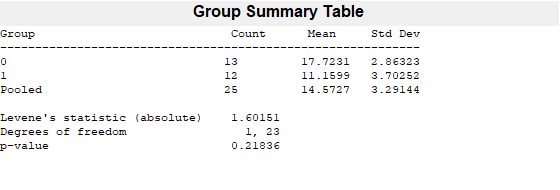

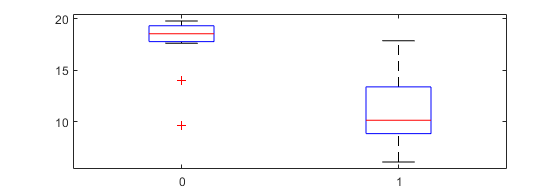

p = 0.2184

group_mg_dsrt = CP_mg_median_dsrt; %create matrix with dsrt + group for vartestn test
group_mg_dsrt(:,2) = 0;
group_mg_dsrt(end+1:end+length(TD_mg_median_dsrt),1) = TD_mg_median_dsrt;
group_mg_dsrt(14:end,2) = 1;
p = vartestn(group_mg_dsrt(:,1),group_mg_dsrt(:,2),'TestType','LeveneAbsolute')

p = vartestn(group_mg_dsrt(:,1),group_mg_dsrt(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.4654

[p,h,stats] = ranksum(CP_mg_median_dsrt,TD_mg_median_dsrt) %Wilcoxon rank sum test

p = 4.5092e-04

h = logical
   1

stats = struct with fields:
       zval: 3.5083
    ranksum: 234

median(CP_mg_median_dsrt)

ans = 18.5554

iqr(CP_mg_median_dsrt)

ans = 1.5507

median(TD_mg_median_dsrt)

ans = 10.1467

iqr(TD_mg_median_dsrt)

ans = 4.5446

### Soleus DSRT normalized by Max ROM - all velocities / medians of participants.

Normalized dynamic stretch reflex data is calculated as follows:

Merged_all.DSRT_sol_maxrom = (35.5 - Merged_all.median_DSRT_fast_Sol./Merged_all.Maximum_ROM. Calculation done in Merge_data.mlx.

 35.5 (max plantarflexion) - DSRT angle = DSRT adjusted to the ROM of the flexibility test. 13 CP, 12 TD.

Both groups have normal distribution and equal variances, an independent t-test with unequal variances was used.

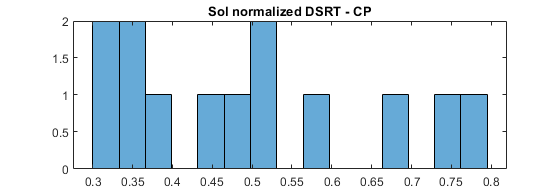

CP_sol_normalized_dsrt = rmmissing(Merged.DSRT_fast_sol_maxrom(Merged.Group == "CP"));
TD_sol_normalized_dsrt = rmmissing(Merged.DSRT_fast_sol_maxrom(Merged.Group == "TD"));
histogram(CP_sol_normalized_dsrt,15),title('Sol normalized DSRT - CP'),

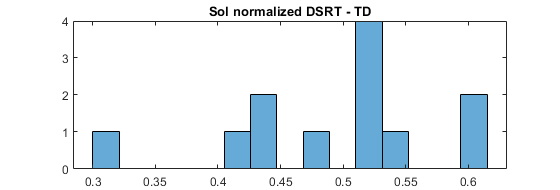

histogram(TD_sol_normalized_dsrt,15), title('Sol normalized DSRT - TD'),

kurtosis_CP = kurtosis(CP_sol_normalized_dsrt)

kurtosis_CP = 2.0635

kurtosis_TD = kurtosis(TD_sol_normalized_dsrt)

kurtosis_TD = 3.2132

skewness_CP = skewness(CP_sol_normalized_dsrt)

skewness_CP = 0.5384

skewness_TD = skewness(TD_sol_normalized_dsrt)

skewness_TD = -0.7168

normalitytest(CP_sol_normalized_dsrt'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6114 	     0.8489                 1 
KS Stephens Modification       0.6497 	     0.1500                 1 
KS Marsaglia Method            0.6114 	     0.7913                 1 
KS Lilliefors Modification     0.1696 	     0.2000                 1 
Anderson-Darling Test          0.4406 	     0.2906                 1 
Cramer- Von Mises Test         0.0613 	     0.3641                 1 
Shapiro-Wilk Test              0.9132 	     0.2030                 1 
Shapiro-Francia Test           0.9302 	     0.2882                 1 
Jarque-Bera Test               1.1031 	     0.5761                 1 
DAgostino & Pearson Test       1.4267 	     0.4900                 1 


normalitytest(TD_sol_normalized_dsrt');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5940 	     0.8721                 1 
KS Stephens Modification       0.6344 	     0.1500                 1 
KS Marsaglia Method            0.5940 	     0.8156                 1 
KS Lilliefors Modification     0.1715 	     0.2000                 1 
Anderson-Darling Test          0.3647 	     0.4376                 1 
Cramer- Von Mises Test         0.0524 	     0.4762                 1 
Shapiro-Wilk Test              0.9334 	     0.4179                 1 
Shapiro-Francia Test           0.9279 	     0.3000                 1 
Jarque-Bera Test               1.0502 	     0.5915                 1 
DAgostino & Pearson Test       2.7366 	     0.2545                 1 


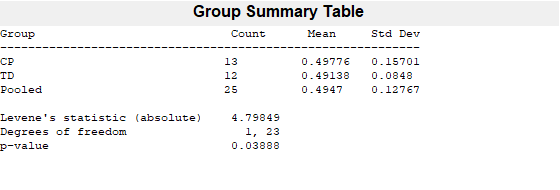

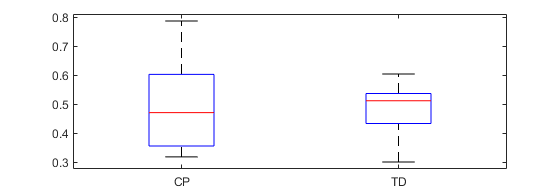

p = 0.0389

p = vartestn(Merged.DSRT_fast_sol_maxrom,Merged.Group,'TestType','LeveneAbsolute')

p = vartestn(Merged.DSRT_fast_sol_maxrom,Merged.Group,'TestType','LeveneQuadratic','display','off')

p = 0.0447

[h,p,ci,stats] = ttest2(CP_sol_normalized_dsrt,TD_sol_normalized_dsrt,'Vartype',"unequal") %independent ttest

h = 0

p = 0.8997

ci =    -0.0983
    0.1110


stats = struct with fields:
    tstat: 0.1278
       df: 18.7411
       sd: [2×1 double]

pwrout = sampsizepwr('t2',[0.5,0.157], 0.49 ,[],13,'Ratio',1.0833)

pwrout = 0.0529

stats_normalized_dsrt_sol = mes(CP_sol_normalized_dsrt,TD_sol_normalized_dsrt,'hedgesg','exactCi',true) %hedge´s g

stats_normalized_dsrt_sol = struct with fields:
            isDep: 0
            nBoot: 0
        confLevel: 0.9500
                n: [2×1 double]
                t: [1×1 struct]
          hedgesg: 0.0484
        hedgesgCi: [2×1 double]
    hedgesgCiType: 'exact analytical'

### MG DSRT normalized by Max ROM - all velocities / medians of participants.

CP is not normally distributed, groups have unequal variances. 13 CP, 12 TD. 

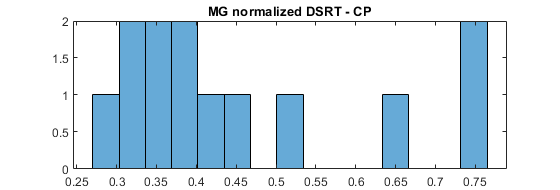

CP_mg_normalized_dsrt = rmmissing(Merged.DSRT_fast_mg_maxrom(Merged.Group == "CP"));
TD_mg_normalized_dsrt = rmmissing(Merged.DSRT_fast_mg_maxrom(Merged.Group == "TD"));
histogram(CP_mg_normalized_dsrt,15),title('MG normalized DSRT - CP'),

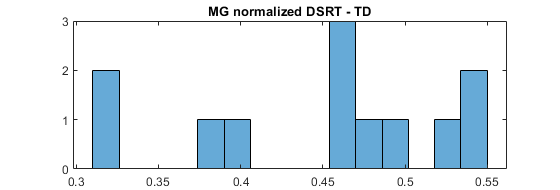

histogram(TD_mg_normalized_dsrt,15), title('MG normalized DSRT - TD'),

kurtosis_CP = kurtosis(CP_mg_normalized_dsrt)

kurtosis_CP = 2.3601

kurtosis_TD = kurtosis(TD_mg_normalized_dsrt)

kurtosis_TD = 2.1763

skewness_CP = skewness(CP_mg_normalized_dsrt)

skewness_CP = 0.9058

skewness_TD = skewness(TD_mg_normalized_dsrt)

skewness_TD = -0.5247

normalitytest(CP_mg_normalized_dsrt'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7383 	     0.6469                 1 
KS Stephens Modification       0.7845 	     0.1392                 1 
KS Marsaglia Method            0.7383 	     0.5777                 1 
KS Lilliefors Modification     0.2048 	     0.1399                 1 
Anderson-Darling Test          0.9350 	     0.0164                 0 
Cramer- Von Mises Test         0.1534 	     0.0215                 0 
Shapiro-Wilk Test              0.8417 	     0.0223                 0 
Shapiro-Francia Test           0.8541 	     0.0321                 0 
Jarque-Bera Test               1.9995 	     0.3680                 1 
DAgostino & Pearson Test       2.8183 	     0.2443                 1 


normalitytest(TD_mg_normalized_dsrt');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6880 	     0.7310                 1 
KS Stephens Modification       0.7348 	     0.1500                 1 
KS Marsaglia Method            0.6880 	     0.6614                 1 
KS Lilliefors Modification     0.1986 	     0.2000                 1 
Anderson-Darling Test          0.4269 	     0.3133                 1 
Cramer- Von Mises Test         0.0635 	     0.3406                 1 
Shapiro-Wilk Test              0.9147 	     0.2448                 1 
Shapiro-Francia Test           0.9309 	     0.3266                 1 
Jarque-Bera Test               0.8898 	     0.6409                 1 
DAgostino & Pearson Test       1.0758 	     0.5840                 1 


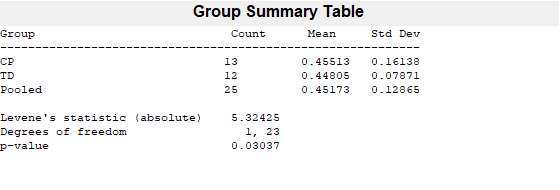

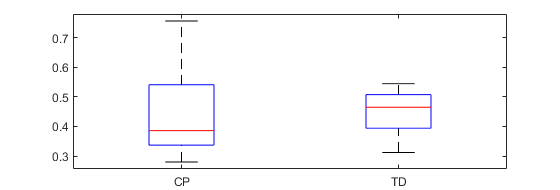

p = 0.0304

p = vartestn(Merged.DSRT_fast_mg_maxrom,Merged.Group,'TestType','LeveneAbsolute')

p = vartestn(Merged.DSRT_fast_mg_maxrom,Merged.Group,'TestType','LeveneQuadratic','display','off')

p = 0.0442

[p,h,stats] = ranksum(CP_mg_normalized_dsrt,TD_mg_normalized_dsrt) %Wilcoxon rank sum test

p = 0.5679

h = logical
   0

stats = struct with fields:
       zval: -0.5711
    ranksum: 158

median(CP_mg_normalized_dsrt)

ans = 0.3858

iqr(CP_mg_normalized_dsrt)

ans = 0.2039

median(TD_mg_normalized_dsrt)

ans = 0.4645

iqr(TD_mg_normalized_dsrt)

ans = 0.1132

### Effects of stretch velocity on Sol stretch reflex onset angle (medians of each CP participant).

Here the median is used to summarize the SRT on each subject in each velocity, thus each row represents a different subject and is adequate for the Friedman test. All 4 velocities are non-normally distributted and have uneven variances. 5117 did not have SR at 50 and 100 deg/s, and thus was excluded from this analysis. 12 CP (2 bad emg, 1 no slow data). Descriptives:

50 deg/s: n = 12, dsrt = 74; 100 deg/s: n = 12, dsrt = 105; 200 deg/s: n = 13, dsrt = 93; 300 deg/s: n = 13, dsrt = 86. % of SR = n of SR in a given velocity divided by 13 participants (15 - 2 EMG data loss) * 10 stretches: 0.57, 0.81, 0.72, 0.66.

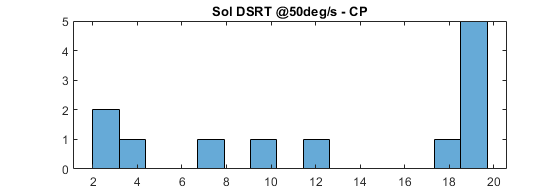

CP_Sol_50_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "50",:), ...
    "Subject",'median','DSRT_Sol_Lat');
CP_Sol_100_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "100",:), ...
    "Subject",'median','DSRT_Sol_Lat');
CP_Sol_200_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "200" & TSRT_Sol.Subject ~= "5117",:), ...
    "Subject",'median','DSRT_Sol_Lat');
CP_Sol_300_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "300" & TSRT_Sol.Subject ~= "5117",:), ...
    "Subject",'median','DSRT_Sol_Lat');
CP_allvel_median_sol = zeros(12,4); %join medians of each subject in 4 cols to use Friedman
CP_allvel_median_sol(:,1) = table2array(CP_Sol_50_median_descriptives(:,3));
CP_allvel_median_sol(:,2) = table2array(CP_Sol_100_median_descriptives(:,3));
CP_allvel_median_sol(:,3) = table2array(CP_Sol_200_median_descriptives(:,3));
CP_allvel_median_sol(:,4) = table2array(CP_Sol_300_median_descriptives(:,3));
CP_Sol_Vel_mediangr(1:12,1) = CP_allvel_median_sol(:,1);%all 4 dsrt in 1 col, 1 col for grouping (vartestn test)
CP_Sol_Vel_mediangr(1:12,2) = 50;
CP_Sol_Vel_mediangr(13:24,1) = CP_allvel_median_sol(:,2);
CP_Sol_Vel_mediangr(13:24,2) = 100;
CP_Sol_Vel_mediangr(25:36,1) = CP_allvel_median_sol(:,3);
CP_Sol_Vel_mediangr(25:36,2) = 200;
CP_Sol_Vel_mediangr(37:48,1) = CP_allvel_median_sol(:,4);
CP_Sol_Vel_mediangr(37:48,2) = 300;
histogram(CP_allvel_median_sol(:,1),15),title('Sol DSRT @50deg/s - CP'),

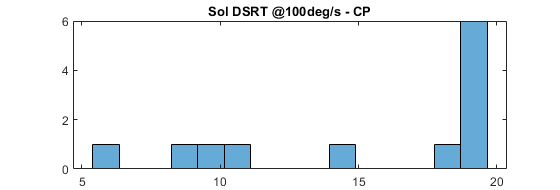

histogram(CP_allvel_median_sol(:,2),15),title('Sol DSRT @100deg/s - CP'),

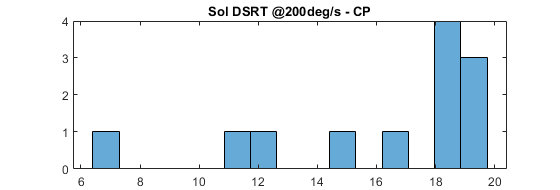

histogram(CP_allvel_median_sol(:,3),15),title('Sol DSRT @200deg/s - CP'),

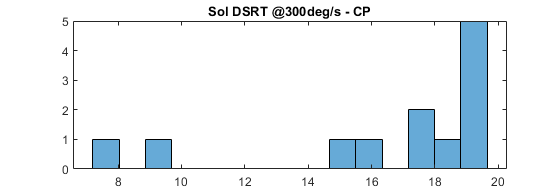

histogram(CP_allvel_median_sol(:,4),15),title('Sol DSRT @300deg/s - CP'),

kurtosis_50 = kurtosis(CP_allvel_median_sol(:,1))

kurtosis_50 = 1.4256

kurtosis_100 = kurtosis(CP_allvel_median_sol(:,2))

kurtosis_100 = 1.9023

kurtosis_200 = kurtosis(CP_allvel_median_sol(:,3))

kurtosis_200 = 3.4423

kurtosis_300 = kurtosis(CP_allvel_median_sol(:,4))

kurtosis_300 = 3.5665

skewness_50 = skewness(CP_allvel_median_sol(:,1))

skewness_50 = -0.3542

skewness_100 = skewness(CP_allvel_median_sol(:,2))

skewness_100 = -0.7221

skewness_200 = skewness(CP_allvel_median_sol(:,3))

skewness_200 = -1.2526

skewness_300 = skewness(CP_allvel_median_sol(:,4))

skewness_300 = -1.4141

normalitytest(CP_allvel_median_sol(:,1)'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9331 	     0.3487                 1 
KS Stephens Modification       0.9965 	     0.0244                 0 
KS Marsaglia Method            0.9331 	     0.2930                 1 
KS Lilliefors Modification     0.2694 	     0.0163                 0 
Anderson-Darling Test          0.9357 	     0.0163                 0 
Cramer- Von Mises Test         0.1448 	     0.0279                 0 
Shapiro-Wilk Test              0.8224 	     0.0170                 0 
Shapiro-Francia Test           0.8513 	     0.0368                 0 
Jarque-Bera Test               1.4903 	     0.4747                 1 
DAgostino & Pearson Test       5.0839 	     0.0787                 1 


normalitytest(CP_allvel_median_sol(:,2)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.1187 	     0.1636                 1 
KS Stephens Modification       1.1947 	     0.0100                 0 
KS Marsaglia Method            1.1187 	     0.1297                 1 
KS Lilliefors Modification     0.3229 	     0.0011                 0 
Anderson-Darling Test          1.3054 	     0.0032                 0 
Cramer- Von Mises Test         0.2290 	     0.0023                 0 
Shapiro-Wilk Test              0.7828 	     0.0060                 0 
Shapiro-Francia Test           0.7976 	     0.0099                 0 
Jarque-Bera Test               1.6453 	     0.4393                 1 
DAgostino & Pearson Test       2.5329 	     0.2818                 1 


normalitytest(CP_allvel_median_sol(:,3)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9245 	     0.3598                 1 
KS Stephens Modification       0.9873 	     0.0269                 0 
KS Marsaglia Method            0.9245 	     0.3031                 1 
KS Lilliefors Modification     0.2669 	     0.0181                 0 
Anderson-Darling Test          1.0575 	     0.0096                 0 
Cramer- Von Mises Test         0.1821 	     0.0091                 0 
Shapiro-Wilk Test              0.8048 	     0.0106                 0 
Shapiro-Francia Test           0.8041 	     0.0116                 0 
Jarque-Bera Test               3.2357 	     0.1983                 1 
DAgostino & Pearson Test       6.3026 	     0.0428                 0 


normalitytest(CP_allvel_median_sol(:,4)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9368 	     0.3440                 1 
KS Stephens Modification       1.0004 	     0.0230                 0 
KS Marsaglia Method            0.9368 	     0.2887                 1 
KS Lilliefors Modification     0.2704 	     0.0155                 0 
Anderson-Darling Test          1.3784 	     0.0024                 0 
Cramer- Von Mises Test         0.2347 	     0.0020                 0 
Shapiro-Wilk Test              0.7518 	     0.0028                 0 
Shapiro-Francia Test           0.7518 	     0.0036                 0 
Jarque-Bera Test               4.1596 	     0.1250                 1 
DAgostino & Pearson Test       7.6961 	     0.0213                 0 


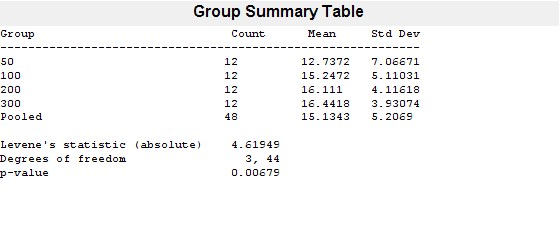

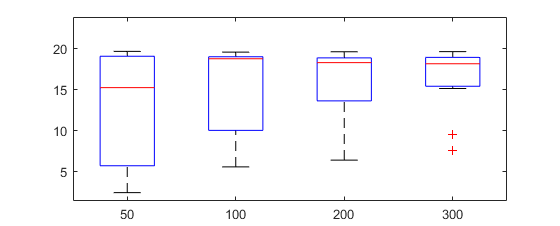

p = 0.0068

p = vartestn(CP_Sol_Vel_mediangr(:,1),CP_Sol_Vel_mediangr(:,2),'TestType','LeveneAbsolute')

p = vartestn(CP_Sol_Vel_mediangr(:,1),CP_Sol_Vel_mediangr(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.0178

[p,tbl,stats] = friedman(CP_allvel_median_sol, 1,'on')

p = 0.5519

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Columns'}    {[ 3.5000]}    {[ 3]}    {[  1.1667]}    {[  2.1000]}    {[     0.5519]}
    {'Error'  }    {[56.5000]}    {[33]}    {[  1.7121]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[60.0000]}    {[47]}    {0×0 double}    {0×0 double}    {0×0 double   }

stats = struct with fields:
       source: 'friedman'
            n: 12
    meanranks: [2.1667 2.5000 2.4167 2.9167]
        sigma: 1.2910


%[c,m,h,gnames] = multcompare(stats,'CType','bonferroni')
median(CP_allvel_median_sol(:,1))

ans = 15.2530

iqr(CP_allvel_median_sol(:,1))

ans = 13.3170

median(CP_allvel_median_sol(:,2))

ans = 18.7631

iqr(CP_allvel_median_sol(:,2))

ans = 8.9637

median(CP_allvel_median_sol(:,3))

ans = 18.2907

iqr(CP_allvel_median_sol(:,3))

ans = 5.2260

median(CP_allvel_median_sol(:,4))

ans = 18.1563

iqr(CP_allvel_median_sol(:,4))

ans = 3.5029

### Effects of stretch velocity on MG stretch reflex onset angle (medians of each CP participant).

5117/5119 did not have SR at all velocities, and thus were excluded from this analysis. 11 CP (2 bad emg + 2 no SR in all velocities). 

1 vector has non-normal distribution (50 deg/s), all have equal variance (quadratic, not absolute). No differences between velocities. 

50 deg/s: n = 12, dsrt = 89; 100 deg/s: n = 12, dsrt = 101; 200 deg/s: n = 13, dsrt = 87; 300 deg/s: n = 13, dsrt = 83. % of SR = n of SR in a given velocity divided by 13 participants (15 - 2 EMG data loss) * 10 stretches: 0.68, 0.78, 0.67, 0.64.

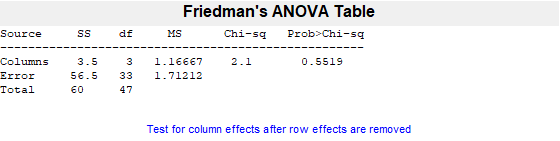

CP_mg_50_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "50" ...
    & TSRT_MG.Subject ~= "5119",:),"Subject",'median','DSRT_MG_Lat');
CP_mg_100_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "100" & TSRT_MG.Subject ~= "5117" ...
    ,:),"Subject",'median','DSRT_MG_Lat');
CP_mg_200_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "200" & TSRT_MG.Subject ~= "5117" ...
    & TSRT_MG.Subject ~= "5119",:),"Subject",'median','DSRT_MG_Lat');
CP_mg_300_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "300"  & TSRT_MG.Subject ~= "5117" ...
    & TSRT_MG.Subject ~= "5119",:),"Subject",'median','DSRT_MG_Lat');
CP_allvel_median_mg = zeros(11,4); %join medians of each subject in 4 cols to use Friedman test
CP_allvel_median_mg(:,1) = table2array(CP_mg_50_median_descriptives(:,3));
CP_allvel_median_mg(:,2) = table2array(CP_mg_100_median_descriptives(:,3));
CP_allvel_median_mg(:,3) = table2array(CP_mg_200_median_descriptives(:,3));
CP_allvel_median_mg(:,4) = table2array(CP_mg_300_median_descriptives(:,3));
CP_MG_Vel_mediangr = CP_allvel_median_mg(:,1);
CP_MG_Vel_mediangr(:,2) = 50;
CP_MG_Vel_mediangr(12:22,1) = CP_allvel_median_mg(:,2);
CP_MG_Vel_mediangr(12:22,2) = 100;
CP_MG_Vel_mediangr(23:33,1) = CP_allvel_median_mg(:,3);
CP_MG_Vel_mediangr(23:33,2) = 200;
CP_MG_Vel_mediangr(34:44,1) = CP_allvel_median_mg(:,4);
CP_MG_Vel_mediangr(34:44,2) = 300;
histogram(CP_allvel_median_mg(:,1),15),title('MG DSRT @50deg/s - CP'),

histogram(CP_allvel_median_mg(:,2),15),title('MG DSRT @100deg/s - CP'),

histogram(CP_allvel_median_mg(:,3),15),title('MG DSRT @200deg/s - CP'),

histogram(CP_allvel_median_mg(:,4),15),title('MG DSRT @300deg/s - CP'),

kurtosis_50 = kurtosis(CP_allvel_median_mg(:,1))

kurtosis_50 = 5.2060

kurtosis_100 = kurtosis(CP_allvel_median_mg(:,2))

kurtosis_100 = 2.3587

kurtosis_200 = kurtosis(CP_allvel_median_mg(:,3))

kurtosis_200 = 2.1291

kurtosis_300 = kurtosis(CP_allvel_median_mg(:,4))

kurtosis_300 = 1.6337

skewness_50 = skewness(CP_allvel_median_mg(:,1))

skewness_50 = -1.8736

skewness_100 = skewness(CP_allvel_median_mg(:,2))

skewness_100 = -0.4697

skewness_200 = skewness(CP_allvel_median_mg(:,3))

skewness_200 = -0.3657

skewness_300 = skewness(CP_allvel_median_mg(:,4))

skewness_300 = -0.2078

normalitytest(CP_allvel_median_mg(:,1)'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.0981 	     0.1792                 1 
KS Stephens Modification       1.1797 	     0.0100                 0 
KS Marsaglia Method            1.0981 	     0.1414                 1 
KS Lilliefors Modification     0.3311 	     0.0014                 0 
Anderson-Darling Test          1.7116 	     0.0006                 0 
Cramer- Von Mises Test         0.3155 	     0.0002                 0 
Shapiro-Wilk Test              0.6726 	     0.0007                 0 
Shapiro-Francia Test           0.6575 	     0.0008                 0 
Jarque-Bera Test               8.6661 	     0.0131                 0 
DAgostino & Pearson Test       15.0705 	     0.0005                 0 


normalitytest(CP_allvel_median_mg(:,2)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4021 	     0.9970                 1 
KS Stephens Modification       0.4320 	     0.1500                 1 
KS Marsaglia Method            0.4021 	     0.9905                 1 
KS Lilliefors Modification     0.1212 	     0.2000                 1 
Anderson-Darling Test          0.2194 	     0.8370                 1 
Cramer- Von Mises Test         0.0299 	     0.8492                 1 
Shapiro-Wilk Test              0.9609 	     0.8247                 1 
Shapiro-Francia Test           0.9663 	     0.8151                 1 
Jarque-Bera Test               0.5931 	     0.7434                 1 
DAgostino & Pearson Test       0.7325 	     0.6933                 1 


normalitytest(CP_allvel_median_mg(:,3)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4703 	     0.9799                 1 
KS Stephens Modification       0.5052 	     0.1500                 1 
KS Marsaglia Method            0.4703 	     0.9579                 1 
KS Lilliefors Modification     0.1418 	     0.2000                 1 
Anderson-Darling Test          0.2614 	     0.7067                 1 
Cramer- Von Mises Test         0.0357 	     0.7600                 1 
Shapiro-Wilk Test              0.9469 	     0.6338                 1 
Shapiro-Francia Test           0.9600 	     0.7249                 1 
Jarque-Bera Test               0.5927 	     0.7435                 1 
DAgostino & Pearson Test       0.5850 	     0.7464                 1 


normalitytest(CP_allvel_median_mg(:,4)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5353 	     0.9368                 1 
KS Stephens Modification       0.5750 	     0.1500                 1 
KS Marsaglia Method            0.5353 	     0.8942                 1 
KS Lilliefors Modification     0.1614 	     0.2000                 1 
Anderson-Darling Test          0.3985 	     0.3654                 1 
Cramer- Von Mises Test         0.0510 	     0.4975                 1 
Shapiro-Wilk Test              0.9111 	     0.2559                 1 
Shapiro-Francia Test           0.9363 	     0.4159                 1 
Jarque-Bera Test               0.9347 	     0.6267                 1 
DAgostino & Pearson Test       2.1707 	     0.3378                 1 


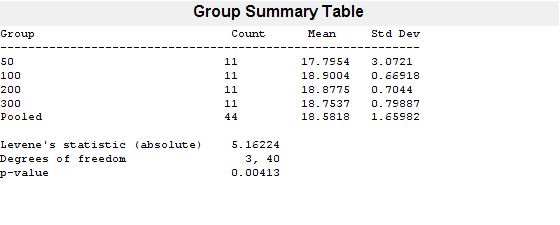

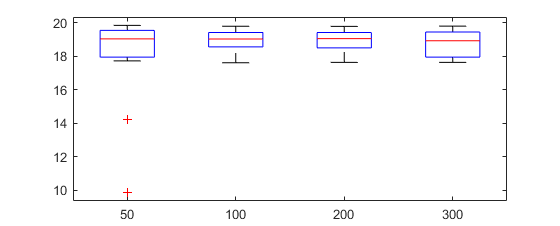

p = 0.0041

p = vartestn(CP_MG_Vel_mediangr(:,1),CP_MG_Vel_mediangr(:,2),'TestType','LeveneAbsolute')

p = vartestn(CP_MG_Vel_mediangr(:,1),CP_MG_Vel_mediangr(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.1135

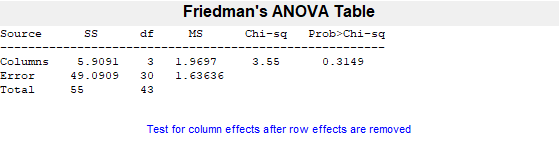

p = 0.3149

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Columns'}    {[ 5.9091]}    {[ 3]}    {[  1.9697]}    {[  3.5455]}    {[     0.3149]}
    {'Error'  }    {[49.0909]}    {[30]}    {[  1.6364]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[     55]}    {[43]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       source: 'friedman'
            n: 11
    meanranks: [3 2.3636 2.6364 2]
        sigma: 1.2910


[p,tbl,stats] = friedman(CP_allvel_median_mg, 1,'on')

%[c,m,h,gnames] = multcompare(stats,'CType','bonferroni')
median(CP_allvel_median_mg(:,1))

ans = 19.0354

iqr(CP_allvel_median_mg(:,1))

ans = 1.6047

median(CP_allvel_median_mg(:,2))

ans = 19.0264

iqr(CP_allvel_median_mg(:,2))

ans = 0.8573

median(CP_allvel_median_mg(:,3))

ans = 19.0493

iqr(CP_allvel_median_mg(:,3))

ans = 0.9128

median(CP_allvel_median_mg(:,4))

ans = 18.9212

iqr(CP_allvel_median_mg(:,4))

ans = 1.4994

### Effects of stretch velocity on Sol stretch reflex onset angle (TD descriptives).

The effects of velocity could not be analyzed due to the low number of dsrt in the lower stretch velocitites. 15 participants, 1 with bad EMG. 

50 deg/s: n = 3, dsrt = 5; 100 deg/s: n = 5, dsrt = 7; 200 deg/s: n = 11, dsrt = 37; 300 deg/s: n = 11, dsrt = 55. Both groups have normal distribution and equal variances, a paired t-test was used to check for differences. % of trials with SR = n of srt in a given velocity divided by 14 participants * 10 trials per velocity = 140. 0.04, 0.05, 0.26 and 0.39.

TD_Sol_50_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "TD" & TSRT_Sol.Velocity_round == "50",:), ...
    "Subject",'median','DSRT_Sol_Lat');
TD_Sol_100_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "TD" & TSRT_Sol.Velocity_round == "100",:), ...
    "Subject",'median','DSRT_Sol_Lat');
TD_Sol_200_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "TD" & TSRT_Sol.Velocity_round == "200",:), ...
    "Subject",'median','DSRT_Sol_Lat');
TD_Sol_300_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "TD" & TSRT_Sol.Velocity_round == "300",:), ...
    "Subject",'median','DSRT_Sol_Lat');


### Effects of stretch velocity on MG stretch reflex onset angle (TD descriptives).

The effects of velocity could not be analyzed due to the low number of dsrt in the lower stretch velocitites. 15 participants, 1 with bad EMG.  

50 deg/s: n = 6, dsrt = 9; 100 deg/s: n = 4, dsrt = 8; 200 deg/s: n = 11, dsrt = 29; 300 deg/s: n = 11, dsrt = 55. Percentage of SR divided by all stretches: 0.06, 0.06, 0.21, 0.39.

TD_MG_50_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "TD" & TSRT_MG.Velocity_round == "50",:), ...
    "Subject",'median','DSRT_MG_Lat');
TD_MG_100_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "TD" & TSRT_MG.Velocity_round == "100",:), ...
    "Subject",'median','DSRT_MG_Lat');
TD_MG_200_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "TD" & TSRT_MG.Velocity_round == "200",:), ...
    "Subject",'median','DSRT_MG_Lat');
TD_MG_300_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "TD" & TSRT_MG.Velocity_round == "300",:), ...
    "Subject",'median','DSRT_MG_Lat');

## `EMG stretch reflex burst`

EMG RMS burst quantified in a 50 ms window at the dsrt, divided by maximum 200ms RMS moving window during a maximal isometric muscle action. Normalized EMG was calculated in Merge_data.mlx: (Merged_all.median_Onset_emg_Sol./Merged_all.max_peak_emgrms_sol_200)

### Soleus Stretch reflex burst response: 2 highest velocities, CP vs. TD.

Since there was a velocity effect for CP, it does not make sense to pool velocities to compare groups. Both groups are not normally distributed, and have unequal variances. 13 CP vs. 12 TD (-2 CP and -1 TD due to bad emg, -2TD with no fast SR). 

CP_sol_fastemg_burst = rmmissing(Merged.EMG_fast_normalized_sol(Merged.Group == "CP"));
TD_sol_fastemg_burst = rmmissing(Merged.EMG_fast_normalized_sol(Merged.Group == "TD"));
histogram(CP_sol_fastemg_burst,15),title('Sol EMG burst - CP'),

histogram(TD_sol_fastemg_burst,15), title('Sol EMG burst - TD'),

kurtosis_CP = kurtosis(CP_sol_fastemg_burst)

kurtosis_CP = 6.5905

kurtosis_TD = kurtosis(TD_sol_fastemg_burst)

kurtosis_TD = 3.4440

skewness_CP = skewness(CP_sol_fastemg_burst)

skewness_CP = 1.9526

skewness_TD = skewness(TD_sol_fastemg_burst)

skewness_TD = 1.1701

normalitytest(CP_sol_fastemg_burst'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7906 	     0.5596                 1 
KS Stephens Modification       0.8401 	     0.0862                 1 
KS Marsaglia Method            0.7906 	     0.4920                 1 
KS Lilliefors Modification     0.2193 	     0.0878                 1 
Anderson-Darling Test          1.0690 	     0.0091                 0 
Cramer- Von Mises Test         0.1574 	     0.0190                 0 
Shapiro-Wilk Test              0.7738 	     0.0034                 0 
Shapiro-Francia Test           0.7510 	     0.0026                 0 
Jarque-Bera Test               15.2436 	     0.0005                 0 
DAgostino & Pearson Test       18.7348 	     0.0001                 0 


normalitytest(TD_sol_fastemg_burst');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7217 	     0.6749                 1 
KS Stephens Modification       0.7707 	     0.1500                 1 
KS Marsaglia Method            0.7217 	     0.6036                 1 
KS Lilliefors Modification     0.2083 	     0.1583                 1 
Anderson-Darling Test          0.7352 	     0.0393                 0 
Cramer- Von Mises Test         0.1228 	     0.0550                 1 
Shapiro-Wilk Test              0.8652 	     0.0568                 1 
Shapiro-Francia Test           0.8601 	     0.0462                 0 
Jarque-Bera Test               2.8371 	     0.2421                 1 
DAgostino & Pearson Test       5.7613 	     0.0561                 1 


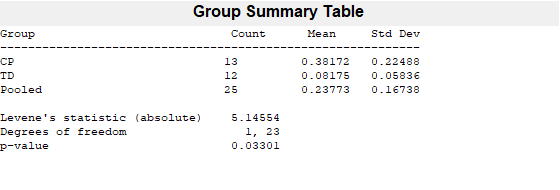

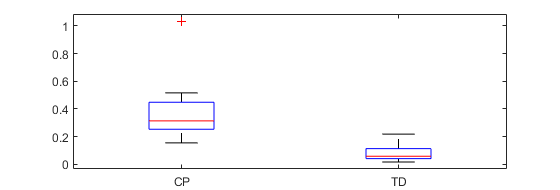

p = 0.0330

p = vartestn(Merged.EMG_fast_normalized_sol,Merged.Group,'TestType','LeveneAbsolute')

p = vartestn(Merged.EMG_fast_normalized_sol,Merged.Group,'TestType','LeveneQuadratic','display','off')

p = 0.2031

[p,h,stats] = ranksum(CP_sol_fastemg_burst,TD_sol_fastemg_burst) %Wilcoxon rank sum test

p = 4.0142e-05

h = logical
   1


stats = struct with fields:
       zval: 4.1067
    ranksum: 245


median(CP_sol_fastemg_burst)

ans = 0.3138

iqr(CP_sol_fastemg_burst)

ans = 0.1943

median(TD_sol_fastemg_burst)

ans = 0.0589

iqr(TD_sol_fastemg_burst)

ans = 0.0721

### MG Stretch reflex burst response: 2 highest velocities, CP vs. TD.

TD does not have a normal distribution and unequal variances.13 CP vs. 12 TD (-2 CP and -1 TD due to bad emg, -2TD with no fast SR). 

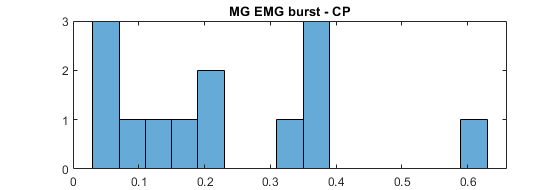

CP_mg_fastemg_burst = rmmissing(Merged.EMG_fast_normalized_mg(Merged.Group == "CP"));
TD_mg_fastemg_burst = rmmissing(Merged.EMG_fast_normalized_mg(Merged.Group == "TD"));
histogram(CP_mg_fastemg_burst,15),title('MG EMG burst - CP'),

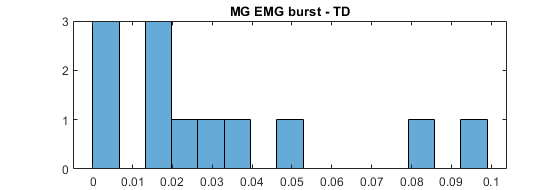

histogram(TD_mg_fastemg_burst,15), title('MG EMG burst - TD'),

kurtosis_CP = kurtosis(CP_mg_fastemg_burst)

kurtosis_CP = 3.1040

kurtosis_TD = kurtosis(TD_mg_fastemg_burst)

kurtosis_TD = 3.1016

skewness_CP = skewness(CP_mg_fastemg_burst)

skewness_CP = 0.8551

skewness_TD = skewness(TD_mg_fastemg_burst)

skewness_TD = 1.1664

normalitytest(CP_mg_fastemg_burst'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5346 	     0.9374                 1 
KS Stephens Modification       0.5681 	     0.1500                 1 
KS Marsaglia Method            0.5346 	     0.8977                 1 
KS Lilliefors Modification     0.1483 	     0.2000                 1 
Anderson-Darling Test          0.5236 	     0.1825                 1 
Cramer- Von Mises Test         0.0704 	     0.2768                 1 
Shapiro-Wilk Test              0.8912 	     0.1013                 1 
Shapiro-Francia Test           0.8937 	     0.0974                 1 
Jarque-Bera Test               1.5903 	     0.4515                 1 
DAgostino & Pearson Test       3.2613 	     0.1958                 1 


normalitytest(TD_mg_fastemg_burst');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7323 	     0.6570                 1 
KS Stephens Modification       0.7821 	     0.1419                 1 
KS Marsaglia Method            0.7323 	     0.5855                 1 
KS Lilliefors Modification     0.2114 	     0.1448                 1 
Anderson-Darling Test          0.8768 	     0.0211                 0 
Cramer- Von Mises Test         0.1417 	     0.0307                 0 
Shapiro-Wilk Test              0.8313 	     0.0218                 0 
Shapiro-Francia Test           0.8367 	     0.0254                 0 
Jarque-Bera Test               2.7261 	     0.2559                 1 
DAgostino & Pearson Test       5.0497 	     0.0801                 1 


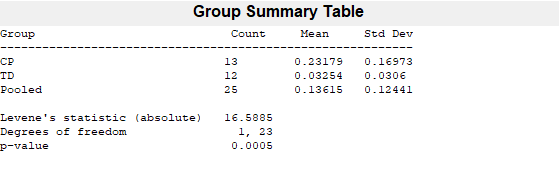

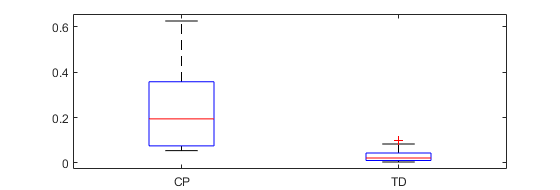

p = 4.6933e-04

p = vartestn(Merged.EMG_fast_normalized_mg,Merged.Group,'TestType','LeveneAbsolute')

p = vartestn(Merged.EMG_fast_normalized_mg,Merged.Group,'TestType','LeveneQuadratic','display','off')

p = 0.0369

[p,h,stats] = ranksum(CP_mg_fastemg_burst,TD_mg_fastemg_burst) %Wilcoxon rank sum test

p = 1.5664e-04

h = logical
   1


stats = struct with fields:
       zval: 3.7803
    ranksum: 239


median(CP_mg_fastemg_burst)

ans = 0.1946

iqr(CP_mg_fastemg_burst)

ans = 0.2826

median(TD_mg_fastemg_burst)

ans = 0.0220

iqr(TD_mg_fastemg_burst)

ans = 0.0333

### Effects of stretch velocity on Sol stretch reflex EMG burst (medians of each CP participant).

12 CP, 5117 did not have dsrt in the slowest velocities. 2 vectors did not have normal distribution. Equal variances.

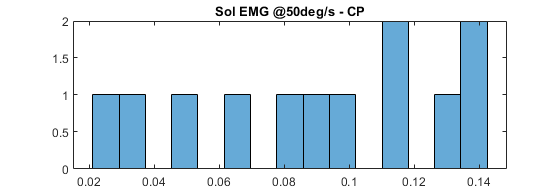

CP_Sol_emg_50_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "50",:), ...
    "Subject",'median','EMG_normalized_sol');
CP_Sol_emg_100_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "100",:), ...
    "Subject",'median','EMG_normalized_sol');
CP_Sol_emg_200_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "200" & TSRT_Sol.Subject ~= "5117",:), ...
    "Subject",'median','EMG_normalized_sol');
CP_Sol_emg_300_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Velocity_round == "300"& TSRT_Sol.Subject ~= "5117",:), ...
    "Subject",'median','EMG_normalized_sol');
CP_allemg_sol = zeros(12,4); %join medians of each subject in 4 cols to use Friedman
CP_allemg_sol(:,1) = table2array(CP_Sol_emg_50_descriptives(:,3));
CP_allemg_sol(:,2) = table2array(CP_Sol_emg_100_descriptives(:,3));
CP_allemg_sol(:,3) = table2array(CP_Sol_emg_200_descriptives(:,3));
CP_allemg_sol(:,4) = table2array(CP_Sol_emg_300_descriptives(:,3));
CP_Sol_emg_gr(1:12,1) = CP_allemg_sol(:,1);%all 4 dsrt in 1 col, 1 col for grouping (vartestn test)
CP_Sol_emg_gr(1:12,2) = 50;
CP_Sol_emg_gr(13:24,1) = CP_allemg_sol(:,2);
CP_Sol_emg_gr(13:24,2) = 100;
CP_Sol_emg_gr(25:36,1) = CP_allemg_sol(:,3);
CP_Sol_emg_gr(25:36,2) = 200;
CP_Sol_emg_gr(37:48,1) = CP_allemg_sol(:,4);
CP_Sol_emg_gr(37:48,2) = 300;
histogram(CP_allemg_sol(:,1),15),title('Sol EMG @50deg/s - CP'),

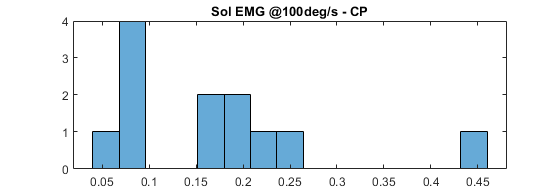

histogram(CP_allemg_sol(:,2),15),title('Sol EMG @100deg/s - CP'),

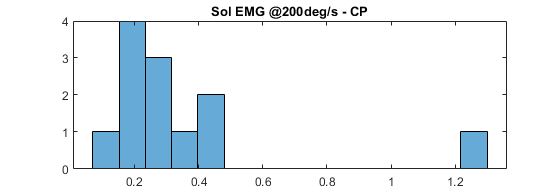

histogram(CP_allemg_sol(:,3),15),title('Sol EMG @200deg/s - CP'),

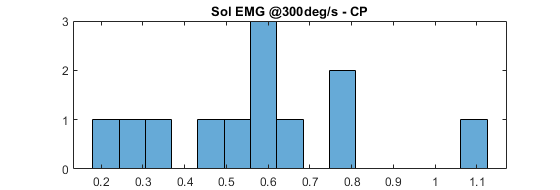

histogram(CP_allemg_sol(:,4),15),title('Sol EMG @300deg/s - CP'),

kurtosis_50 = kurtosis(CP_allemg_sol(:,1))

kurtosis_50 = 1.7215

kurtosis_100 = kurtosis(CP_allemg_sol(:,2))

kurtosis_100 = 4.6576

kurtosis_200 = kurtosis(CP_allemg_sol(:,3))

kurtosis_200 = 8.4221

kurtosis_300 = kurtosis(CP_allemg_sol(:,4))

kurtosis_300 = 3.2311

skewness_50 = skewness(CP_allemg_sol(:,1))

skewness_50 = -0.2688

skewness_100 = skewness(CP_allemg_sol(:,2))

skewness_100 = 1.4180

skewness_200 = skewness(CP_allemg_sol(:,3))

skewness_200 = 2.5535

skewness_300 = skewness(CP_allemg_sol(:,4))

skewness_300 = 0.5677

normalitytest(CP_allemg_sol(:,1)'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5514 	     0.9214                 1 
KS Stephens Modification       0.5888 	     0.1500                 1 
KS Marsaglia Method            0.5514 	     0.8753                 1 
KS Lilliefors Modification     0.1592 	     0.2000                 1 
Anderson-Darling Test          0.3434 	     0.4894                 1 
Cramer- Von Mises Test         0.0467 	     0.5604                 1 
Shapiro-Wilk Test              0.9278 	     0.3578                 1 
Shapiro-Francia Test           0.9496 	     0.5407                 1 
Jarque-Bera Test               0.9619 	     0.6182                 1 
DAgostino & Pearson Test       1.9338 	     0.3803                 1 


normalitytest(CP_allemg_sol(:,2)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6025 	     0.8609                 1 
KS Stephens Modification       0.6435 	     0.1500                 1 
KS Marsaglia Method            0.6025 	     0.8026                 1 
KS Lilliefors Modification     0.1739 	     0.2000                 1 
Anderson-Darling Test          0.7055 	     0.0448                 0 
Cramer- Von Mises Test         0.0943 	     0.1347                 1 
Shapiro-Wilk Test              0.8418 	     0.0291                 0 
Shapiro-Francia Test           0.8302 	     0.0216                 0 
Jarque-Bera Test               5.3950 	     0.0674                 1 
DAgostino & Pearson Test       10.2995 	     0.0058                 0 


normalitytest(CP_allemg_sol(:,3)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.1554 	     0.1385                 1 
KS Stephens Modification       1.2339 	     0.0100                 0 
KS Marsaglia Method            1.1554 	     0.1084                 1 
KS Lilliefors Modification     0.3335 	     0.0006                 0 
Anderson-Darling Test          1.9259 	     0.0002                 0 
Cramer- Von Mises Test         0.3249 	     0.0002                 0 
Shapiro-Wilk Test              0.6101 	     0.0001                 0 
Shapiro-Francia Test           0.5810 	     0.0002                 0 
Jarque-Bera Test               27.7404 	     0.0000                 0 
DAgostino & Pearson Test       27.1352 	     0.0000                 0 


normalitytest(CP_allemg_sol(:,4)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5270 	     0.9440                 1 
KS Stephens Modification       0.5628 	     0.1500                 1 
KS Marsaglia Method            0.5270 	     0.9053                 1 
KS Lilliefors Modification     0.1521 	     0.2000                 1 
Anderson-Darling Test          0.2741 	     0.6640                 1 
Cramer- Von Mises Test         0.0362 	     0.7499                 1 
Shapiro-Wilk Test              0.9540 	     0.6964                 1 
Shapiro-Francia Test           0.9457 	     0.4883                 1 
Jarque-Bera Test               0.6713 	     0.7149                 1 
DAgostino & Pearson Test       2.1449 	     0.3422                 1 


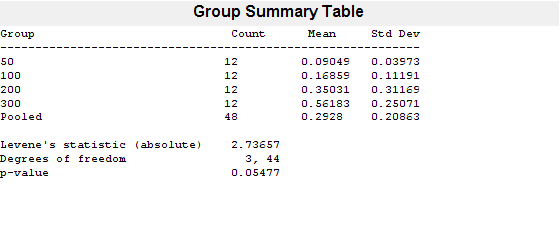

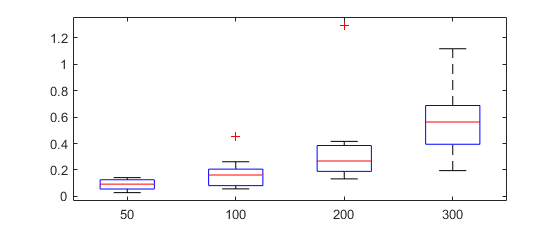

p = 0.0548

p = vartestn(CP_Sol_emg_gr(:,1),CP_Sol_emg_gr(:,2),'TestType','LeveneAbsolute')

p = vartestn(CP_Sol_emg_gr(:,1),CP_Sol_emg_gr(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.3584

[p,tbl,stats] = friedman(CP_allemg_sol, 1,'on')

p = 3.3810e-07

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Columns'}    {[54.8333]}    {[ 3]}    {[ 18.2778]}    {[ 32.9000]}    {[ 3.3810e-07]}
    {'Error'  }    {[ 5.1667]}    {[33]}    {[  0.1566]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[     60]}    {[47]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       source: 'friedman'
            n: 12
    meanranks: [1.0833 1.9167 3.1667 3.8333]
        sigma: 1.2910


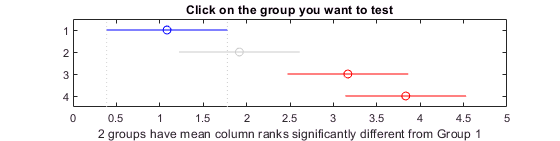

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


c =     1.0000    2.0000   -2.2238   -0.8333    0.5572    0.6831
    1.0000    3.0000   -3.4738   -2.0833   -0.6928    0.0005
    1.0000    4.0000   -4.1405   -2.7500   -1.3595    0.0000
    2.0000    3.0000   -2.6405   -1.2500    0.1405    0.1062
    2.0000    4.0000   -3.3072   -1.9167   -0.5262    0.0017
    3.0000    4.0000   -2.0572   -0.6667    0.7238    1.0000


m =     1.0833    0.3727
    1.9167    0.3727
    3.1667    0.3727
    3.8333    0.3727


h =   Figure (51: Multiple comparison of mean column ranks) with properties:

      Number: 51
        Name: 'Multiple comparison of mean column ranks'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 838.2000 560 140.8000]
       Units: 'pixels'

  Show all properties


gnames = 4×1 char array
    '1'
    '2'
    '3'
    '4'


[c,m,h,gnames] = multcompare(stats,'CType','bonferroni')

median(CP_allemg_sol(:,1))

ans = 0.0927

iqr(CP_allemg_sol(:,1))

ans = 0.0701

median(CP_allemg_sol(:,2))

ans = 0.1611

iqr(CP_allemg_sol(:,2))

ans = 0.1251

median(CP_allemg_sol(:,3))

ans = 0.2673

iqr(CP_allemg_sol(:,3))

ans = 0.1961

median(CP_allemg_sol(:,4))

ans = 0.5629

iqr(CP_allemg_sol(:,4))

ans = 0.2935

### Effects of stretch velocity on MG stretch reflex EMG burst (medians of each CP participant).

11 CP, 5117/5119 did not have dsrt in sol in the slowest velocities. 1 vector was not normally distributed (200 deg/s), unequal absolute variance, but equal quadratic variance.

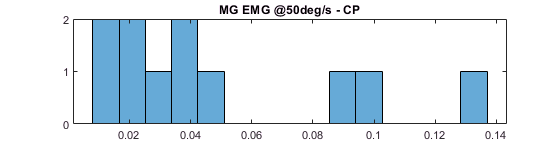

CP_mg_emg_50_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "50" & TSRT_MG.Subject ~= "5117" ...
  & TSRT_MG.Subject ~= "5119"  ,:), "Subject",'median','EMG_normalized_mg');
CP_mg_emg_100_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "100" & TSRT_MG.Subject ~= "5117" ...
  & TSRT_MG.Subject ~= "5119"  ,:), "Subject",'median','EMG_normalized_mg');
CP_mg_emg_200_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "200" & TSRT_MG.Subject ~= "5117" ...
  & TSRT_MG.Subject ~= "5119"  ,:), "Subject",'median','EMG_normalized_mg');
CP_mg_emg_300_descriptives = groupsummary(TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Velocity_round == "300" & TSRT_MG.Subject ~= "5117" ...
    & TSRT_MG.Subject ~= "5119"  ,:), "Subject",'median','EMG_normalized_mg');
CP_allemg_mg = zeros(11,4); %join medians of each subject in 4 cols to use Friedman
CP_allemg_mg(:,1) = table2array(CP_mg_emg_50_descriptives(:,3));
CP_allemg_mg(:,2) = table2array(CP_mg_emg_100_descriptives(:,3));
CP_allemg_mg(:,3) = table2array(CP_mg_emg_200_descriptives(:,3));
CP_allemg_mg(:,4) = table2array(CP_mg_emg_300_descriptives(:,3));
CP_mg_emg_gr(1:11,1) = CP_allemg_mg(:,1);%all 4 dsrt in 1 col, 1 col for grouping (vartestn test)
CP_mg_emg_gr(1:11,2) = 50;
CP_mg_emg_gr(12:22,1) = CP_allemg_mg(:,2);
CP_mg_emg_gr(12:22,2) = 100;
CP_mg_emg_gr(23:33,1) = CP_allemg_mg(:,3);
CP_mg_emg_gr(23:33,2) = 200;
CP_mg_emg_gr(34:44,1) = CP_allemg_mg(:,4);
CP_mg_emg_gr(34:44,2) = 300;
histogram(CP_allemg_mg(:,1),15),title('MG EMG @50deg/s - CP'),

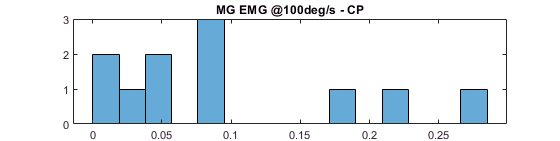

histogram(CP_allemg_mg(:,2),15),title('MG EMG @100deg/s - CP'),

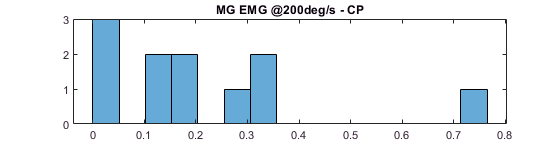

histogram(CP_allemg_mg(:,3),15),title('MG EMG @200deg/s - CP'),

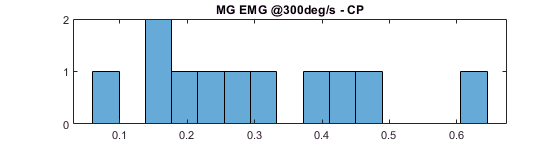

histogram(CP_allemg_mg(:,4),15),title('MG EMG @300deg/s - CP'),

kurtosis_50 = kurtosis(CP_allemg_mg(:,1))

kurtosis_50 = 2.8377

kurtosis_100 = kurtosis(CP_allemg_mg(:,2))

kurtosis_100 = 2.7347

kurtosis_200 = kurtosis(CP_allemg_mg(:,3))

kurtosis_200 = 5.1468

kurtosis_300 = kurtosis(CP_allemg_mg(:,4))

kurtosis_300 = 2.5078

skewness_50 = skewness(CP_allemg_mg(:,1))

skewness_50 = 0.9960

skewness_100 = skewness(CP_allemg_mg(:,2))

skewness_100 = 0.9561

skewness_200 = skewness(CP_allemg_mg(:,3))

skewness_200 = 1.6375

skewness_300 = skewness(CP_allemg_mg(:,4))

skewness_300 = 0.5704

normalitytest(CP_allemg_mg(:,1)'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7631 	     0.6051                 1 
KS Stephens Modification       0.8198 	     0.0995                 1 
KS Marsaglia Method            0.7631 	     0.5314                 1 
KS Lilliefors Modification     0.2301 	     0.1073                 1 
Anderson-Darling Test          0.6680 	     0.0528                 1 
Cramer- Von Mises Test         0.1161 	     0.0678                 1 
Shapiro-Wilk Test              0.8724 	     0.0874                 1 
Shapiro-Francia Test           0.8746 	     0.0818                 1 
Jarque-Bera Test               1.8307 	     0.4004                 1 
DAgostino & Pearson Test       3.4914 	     0.1745                 1 


normalitytest(CP_allemg_mg(:,2)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9232 	     0.3615                 1 
KS Stephens Modification       0.9917 	     0.0258                 0 
KS Marsaglia Method            0.9232 	     0.3024                 1 
KS Lilliefors Modification     0.2783 	     0.0171                 0 
Anderson-Darling Test          0.6630 	     0.0540                 1 
Cramer- Von Mises Test         0.1178 	     0.0643                 1 
Shapiro-Wilk Test              0.8743 	     0.0921                 1 
Shapiro-Francia Test           0.8783 	     0.0901                 1 
Jarque-Bera Test               1.7080 	     0.4257                 1 
DAgostino & Pearson Test       3.1250 	     0.2096                 1 


normalitytest(CP_allemg_mg(:,3)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7570 	     0.6154                 1 
KS Stephens Modification       0.8132 	     0.1066                 1 
KS Marsaglia Method            0.7570 	     0.5416                 1 
KS Lilliefors Modification     0.2282 	     0.1139                 1 
Anderson-Darling Test          0.8471 	     0.0241                 0 
Cramer- Von Mises Test         0.1223 	     0.0559                 1 
Shapiro-Wilk Test              0.8019 	     0.0136                 0 
Shapiro-Francia Test           0.7872 	     0.0103                 0 
Jarque-Bera Test               7.0281 	     0.0298                 0 
DAgostino & Pearson Test       13.1003 	     0.0014                 0 


normalitytest(CP_allemg_mg(:,4)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5002 	     0.9638                 1 
KS Stephens Modification       0.5374 	     0.1500                 1 
KS Marsaglia Method            0.5002 	     0.9326                 1 
KS Lilliefors Modification     0.1508 	     0.2000                 1 
Anderson-Darling Test          0.2613 	     0.7071                 1 
Cramer- Von Mises Test         0.0369 	     0.7376                 1 
Shapiro-Wilk Test              0.9548 	     0.7435                 1 
Shapiro-Francia Test           0.9559 	     0.6656                 1 
Jarque-Bera Test               0.7075 	     0.7020                 1 
DAgostino & Pearson Test       1.1179 	     0.5718                 1 


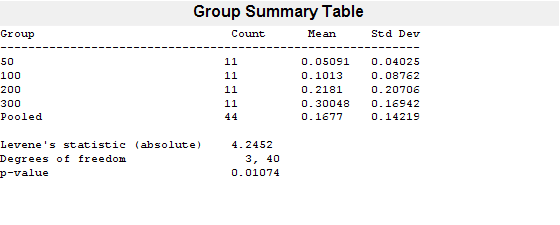

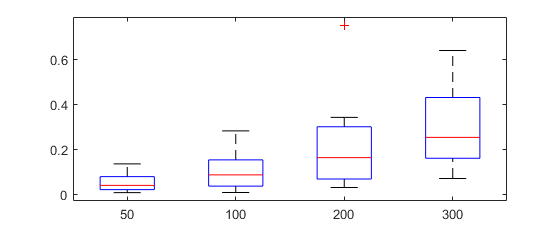

p = 0.0107

p = vartestn(CP_mg_emg_gr(:,1),CP_mg_emg_gr(:,2),'TestType','LeveneAbsolute')

p = vartestn(CP_mg_emg_gr(:,1),CP_mg_emg_gr(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.2005

[p,tbl,stats] = friedman(CP_allemg_mg, 1,'on')

p = 5.4695e-07

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Columns'}    {[53.1818]}    {[ 3]}    {[ 17.7273]}    {[ 31.9091]}    {[ 5.4695e-07]}
    {'Error'  }    {[ 1.8182]}    {[30]}    {[  0.0606]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[     55]}    {[43]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       source: 'friedman'
            n: 11
    meanranks: [1 2 3.0909 3.9091]
        sigma: 1.2910


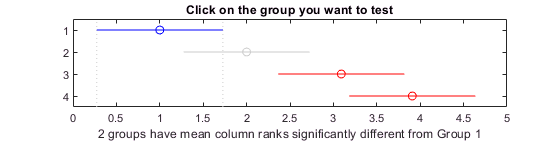

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


c =     1.0000    2.0000   -2.4523   -1.0000    0.4523    0.4157
    1.0000    3.0000   -3.5432   -2.0909   -0.6386    0.0009
    1.0000    4.0000   -4.3614   -2.9091   -1.4568    0.0000
    2.0000    3.0000   -2.5432   -1.0909    0.3614    0.2851
    2.0000    4.0000   -3.3614   -1.9091   -0.4568    0.0031
    3.0000    4.0000   -2.2705   -0.8182    0.6341    0.8232


m =     1.0000    0.3892
    2.0000    0.3892
    3.0909    0.3892
    3.9091    0.3892


h =   Figure (54: Multiple comparison of mean column ranks) with properties:

      Number: 54
        Name: 'Multiple comparison of mean column ranks'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 838.2000 560 140.8000]
       Units: 'pixels'

  Show all properties


gnames = 4×1 char array
    '1'
    '2'
    '3'
    '4'


[c,m,h,gnames] = multcompare(stats,'CType','bonferroni')

median(CP_allemg_mg(:,1))

ans = 0.0410

iqr(CP_allemg_mg(:,1))

ans = 0.0582

median(CP_allemg_mg(:,2))

ans = 0.0881

iqr(CP_allemg_mg(:,2))

ans = 0.1170

median(CP_allemg_mg(:,3))

ans = 0.1646

iqr(CP_allemg_mg(:,3))

ans = 0.2327

median(CP_allemg_mg(:,4))

ans = 0.2552

iqr(CP_allemg_mg(:,4))

ans = 0.2702

## `Common range - Hyper-resistance`

13 CP, 14 TD (all due to emg). Small negative values means that there was no resistance and the offset correction was not precise enough, so they are turned to zero. 

TSRT_mechanics = TSRT_mechanics_all(TSRT_mechanics_all.Subject ~= "5105", :);%exclude case study
CP_mechanics_descriptives = groupsummary(TSRT_mechanics(TSRT_mechanics.Group == "CP",:), "Subject",'median',{'PeakTorque_50','PeakTorque_100', ...
   'TotalEnergy_50','TotalEnergy_100'});
TD_mechanics_descriptives = groupsummary(TSRT_mechanics(TSRT_mechanics.Group == "TD",:), "Subject",'median',{'PeakTorque_50','PeakTorque_100', ...
   'TotalEnergy_50','TotalEnergy_100'});

#### Peak torque 50 deg/s - CP vs. TD.

TD data is not normal, groups have unequal variances. 

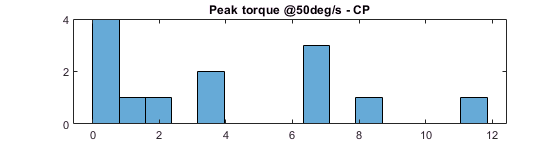

CP_PT50 = CP_mechanics_descriptives.median_PeakTorque_50;
CP_PT50 (CP_PT50 < 0) = 0; % negative values are removed
TD_PT50 = TD_mechanics_descriptives.median_PeakTorque_50;
TD_PT50 (TD_PT50 < 0) = 0; % negative values are removed
histogram(CP_PT50,15),title('Peak torque @50deg/s - CP'),

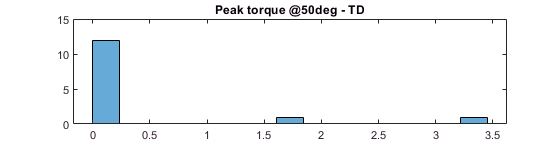

histogram(TD_PT50,15),title('Peak torque @50deg - TD'),

kurtosis_CP = kurtosis(CP_PT50)

kurtosis_CP = 2.2354

kurtosis_TD = kurtosis(TD_PT50)

kurtosis_TD = 7.9764

skewness_CP = skewness(CP_PT50)

skewness_CP = 0.6404

skewness_TD = skewness(TD_PT50)

skewness_TD = 2.5253

normalitytest(CP_PT50');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6856 	     0.7351                 1 
KS Stephens Modification       0.7285 	     0.1500                 1 
KS Marsaglia Method            0.6856 	     0.6678                 1 
KS Lilliefors Modification     0.1901 	     0.2000                 1 
Anderson-Darling Test          0.5992 	     0.1175                 1 
Cramer- Von Mises Test         0.0980 	     0.1200                 1 
Shapiro-Wilk Test              0.8919 	     0.1036                 1 
Shapiro-Francia Test           0.9037 	     0.1310                 1 
Jarque-Bera Test               1.2054 	     0.5473                 1 
DAgostino & Pearson Test       1.5570 	     0.4591                 1 


normalitytest(TD_PT50');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.8738 	     0.0018                 0 
KS Stephens Modification       1.9826 	     0.0100                 0 
KS Marsaglia Method            1.8738 	     0.0009                 0 
KS Lilliefors Modification     0.5008 	     0.0000                 0 
Anderson-Darling Test          4.0874 	     0.0000                 0 
Cramer- Von Mises Test         0.8281 	     0.0000                 0 
Shapiro-Wilk Test              0.4366 	     0.0000                 0 
Shapiro-Francia Test           0.4130 	     0.0000                 0 
Jarque-Bera Test               29.3257 	     0.0000                 0 
DAgostino & Pearson Test       26.0386 	     0.0000                 0 


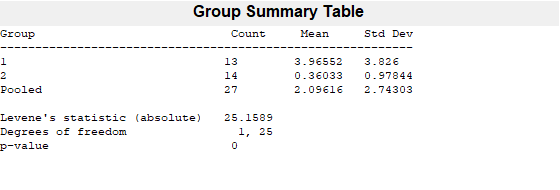

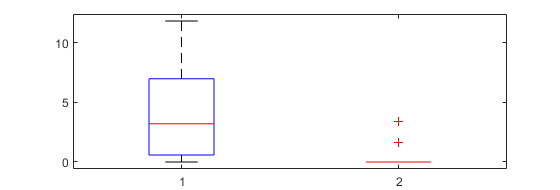

p = 3.5773e-05

PT50_gr = CP_PT50;
PT50_gr(:,2) = 1;
PT50_gr (14:27,1) = TD_PT50;
PT50_gr (14:27,2) = 2;
p = vartestn(PT50_gr(:,1),PT50_gr(:,2),'TestType','LeveneAbsolute')

p = vartestn(PT50_gr(:,1),PT50_gr(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.0062

[p,h,stats] = ranksum(CP_PT50,TD_PT50) %Wilcoxon rank sum test

p = 6.1432e-04

h = logical
   1


stats = struct with fields:
       zval: 3.4252
    ranksum: 248


median(CP_PT50)

ans = 3.2053

iqr(CP_PT50)

ans = 6.3933

median(TD_PT50)

ans = 0

iqr(TD_PT50)

ans = 0

#### Peak torque 100 deg/s - CP vs. TD.

TD does not have normal distribution, and groups have unequal variances.

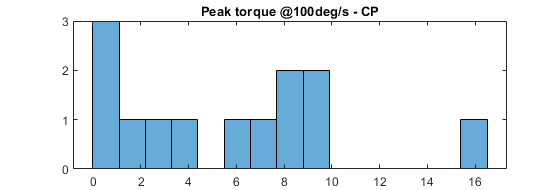

CP_PT100 = CP_mechanics_descriptives.median_PeakTorque_100;
CP_PT100 (CP_PT100 < 0) = 0;
TD_PT100 = TD_mechanics_descriptives.median_PeakTorque_100;
TD_PT100 (TD_PT100 < 0) = 0;
histogram(CP_PT100,15),title('Peak torque @100deg/s - CP'),

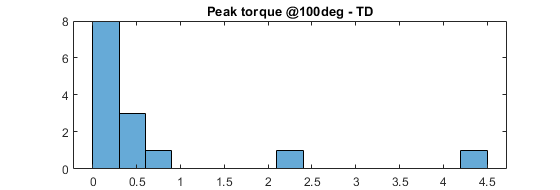

histogram(TD_PT100,15),title('Peak torque @100deg - TD'),

kurtosis_CP = kurtosis(CP_PT100)

kurtosis_CP = 2.8962

kurtosis_TD = kurtosis(TD_PT100)

kurtosis_TD = 7.5006

skewness_CP = skewness(CP_PT100)

skewness_CP = 0.6419

skewness_TD = skewness(TD_PT100)

skewness_TD = 2.3806

normalitytest(CP_PT100');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4726 	     0.9788                 1 
KS Stephens Modification       0.5022 	     0.1500                 1 
KS Marsaglia Method            0.4726 	     0.9576                 1 
KS Lilliefors Modification     0.1311 	     0.2000                 1 
Anderson-Darling Test          0.3518 	     0.4684                 1 
Cramer- Von Mises Test         0.0407 	     0.6696                 1 
Shapiro-Wilk Test              0.9253 	     0.2958                 1 
Shapiro-Francia Test           0.9278 	     0.2690                 1 
Jarque-Bera Test               0.8985 	     0.6381                 1 
DAgostino & Pearson Test       1.8704 	     0.3925                 1 


normalitytest(TD_PT100');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.3537 	     0.0512                 1 
KS Stephens Modification       1.4322 	     0.0100                 0 
KS Marsaglia Method            1.3537 	     0.0379                 0 
KS Lilliefors Modification     0.3618 	     0.0000                 0 
Anderson-Darling Test          2.6157 	     0.0000                 0 
Cramer- Von Mises Test         0.4955 	     0.0000                 0 
Shapiro-Wilk Test              0.5798 	     0.0000                 0 
Shapiro-Francia Test           0.5595 	     0.0001                 0 
Jarque-Bera Test               25.0387 	     0.0000                 0 
DAgostino & Pearson Test       24.0160 	     0.0000                 0 


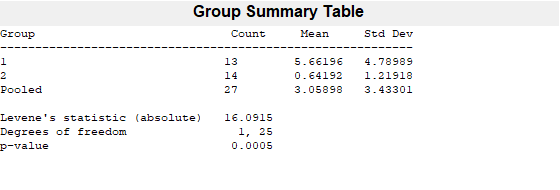

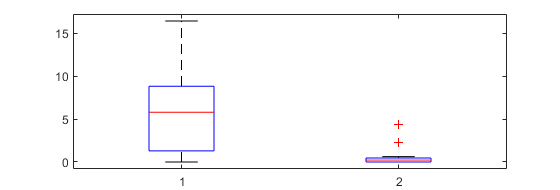

p = 4.8112e-04

PT100_gr = CP_PT100;
PT100_gr(:,2) = 1;
PT100_gr (14:27,1) = TD_PT100;
PT100_gr (14:27,2) = 2;
p = vartestn(PT100_gr(:,1),PT100_gr(:,2),'TestType','LeveneAbsolute')

p = vartestn(PT100_gr(:,1),PT100_gr(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.0229

[p,h,stats] = ranksum(CP_PT100,TD_PT100) %Wilcoxon rank sum test

p = 0.0026

h = logical
   1


stats = struct with fields:
       zval: 3.0102
    ranksum: 244


median(CP_PT100)

ans = 5.7918

iqr(CP_PT100)

ans = 7.5164

median(TD_PT100)

ans = 0.2203

iqr(TD_PT100)

ans = 0.4598

#### Total energy 50 deg/s - CP vs. TD.

Groups are not normally distributed and have unequal variances. 

% CP_TE50 = CP_mechanics_descriptives.median_TotalEnergy_50;
% CP_TE50 (CP_TE50 < 0) = 0;
% TD_TE50 = TD_mechanics_descriptives.median_TotalEnergy_50;
% TD_TE50 (TD_TE50 < 0) = 0;
% histogram(CP_TE50,15),title('Total Energy @50deg/s - CP'),
% histogram(TD_TE50,15),title('Total Energy @50deg - TD'),
% kurtosis_CP = kurtosis(CP_TE50)
% kurtosis_TD = kurtosis(TD_TE50)
% skewness_CP = skewness(CP_TE50)
% skewness_TD = skewness(TD_TE50)
% normalitytest(CP_TE50');
% normalitytest(TD_TE50');
% PT100_gr = CP_TE50;
% PT100_gr(:,2) = 1;
% PT100_gr (14:28,1) = TD_TE50;
% PT100_gr (14:28,2) = 2;
% p = vartestn(PT100_gr(:,1),PT100_gr(:,2),'TestType','LeveneAbsolute')
% p = vartestn(PT100_gr(:,1),PT100_gr(:,2),'TestType','LeveneQuadratic','display','off')
% [p,h,stats] = ranksum(CP_TE50,TD_TE50) %Wilcoxon rank sum test
% median(CP_TE50)
% iqr(CP_TE50)
% median(TD_TE50)
% iqr(TD_TE50)

#### Total energy 100 deg/s - CP vs. TD.

Groups are not normally distributed and have unequal variances. 

% CP_TE100 = CP_mechanics_descriptives.median_TotalEnergy_100;
% CP_TE100 (CP_TE100 <0) = 0;
% TD_TE100 = TD_mechanics_descriptives.median_TotalEnergy_100;
% TD_TE100 (TD_TE100 <0) = 0;
% histogram(CP_TE100,15),title('Total Energy @50deg/s - CP'),
% histogram(TD_TE100,15),title('Total Energy @50deg - TD'),
% kurtosis_CP = kurtosis(CP_TE100)
% kurtosis_TD = kurtosis(TD_TE100)
% skewness_CP = skewness(CP_TE100)
% skewness_TD = skewness(TD_TE100)
% normalitytest(CP_TE100');
% normalitytest(TD_TE100');
% PT100_gr = CP_TE100;
% PT100_gr(:,2) = 1;
% PT100_gr (14:28,1) = TD_TE100;
% PT100_gr (14:28,2) = 2;
% p = vartestn(PT100_gr(:,1),PT100_gr(:,2),'TestType','LeveneAbsolute')
% p = vartestn(PT100_gr(:,1),PT100_gr(:,2),'TestType','LeveneQuadratic','display','off')
% [p,h,stats] = ranksum(CP_TE100,TD_TE100) %Wilcoxon rank sum test
% median(CP_TE100)
% iqr(CP_TE100)
% median(TD_TE100)
% iqr(TD_TE100)

### Calculating true velocity

The velocities asked to the dynamometer were: 50,100,200 and 300 deg/s. The true velocities according to the linear potentiometer were: 55, 110, 210, 291.

True_vel = groupsummary(TSRT_main, "Velocity_round", {'median', 'mean','std'}, 'Velocity');
True_vel.cv = True_vel.std_Velocity./True_vel.mean_Velocity

True_vel = 4×6 table
    Velocity_round    GroupCount    median_Velocity    mean_Velocity    std_Velocity       cv   
    ______________    __________    _______________    _____________    ____________    ________

         50              238               55             55.651           1.1214       0.020151
         100             251              110             110.22           2.8366       0.025735
         200             233              213             210.64           8.7246        0.04142
         300             221              294             291.63           16.311       0.055932


### Small groups used for machine learning - DSRT Sol

12 CP + 10 TD. Verifying ig groups are different regarding hyperreflexia vars. CP does not have a normal distribution. Groups are statistically different.

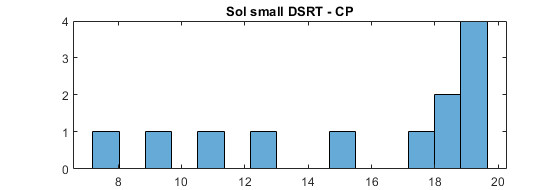

CP_sol_small_dsrt = rmmissing(Merged.median_fast_DSRT_sol(Merged.Group == "CP" & Merged.Subject ~= "5102" & Merged.Subject ~= "5116",:)); 
TD_sol_small_dsrt = rmmissing(Merged.median_fast_DSRT_sol(Merged.Group == "TD" & Merged.Subject ~= "5202" & Merged.Subject ~= "5208" ...
    & Merged.Subject ~= "5209" & Merged.Subject ~= "5217" & Merged.Subject ~= "5218",:)); 
histogram(CP_sol_small_dsrt,15),title('Sol small DSRT - CP'),

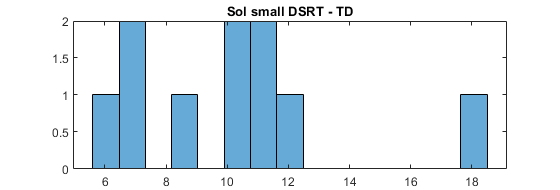

histogram(TD_sol_small_dsrt,15), title('Sol small DSRT - TD'),

kurtosis_CP = kurtosis(CP_sol_small_dsrt)

kurtosis_CP = 2.0514

kurtosis_TD = kurtosis(TD_sol_small_dsrt)

kurtosis_TD = 3.8137

skewness_CP = skewness(CP_sol_small_dsrt)

skewness_CP = -0.7744

skewness_TD = skewness(TD_sol_small_dsrt)

skewness_TD = 1.0544

normalitytest(CP_sol_small_dsrt'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8951 	     0.3996                 1 
KS Stephens Modification       0.9559 	     0.0348                 0 
KS Marsaglia Method            0.8951 	     0.3394                 1 
KS Lilliefors Modification     0.2584 	     0.0261                 0 
Anderson-Darling Test          0.9873 	     0.0130                 0 
Cramer- Von Mises Test         0.1713 	     0.0126                 0 
Shapiro-Wilk Test              0.8263 	     0.0190                 0 
Shapiro-Francia Test           0.8414 	     0.0285                 0 
Jarque-Bera Test               1.6492 	     0.4384                 1 
DAgostino & Pearson Test       2.3444 	     0.3097                 1 


normalitytest(TD_sol_small_dsrt');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7198 	     0.6780                 1 
KS Stephens Modification       0.7787 	     0.1458                 1 
KS Marsaglia Method            0.7198 	     0.6013                 1 
KS Lilliefors Modification     0.2276 	     0.1517                 1 
Anderson-Darling Test          0.5269 	     0.1791                 1 
Cramer- Von Mises Test         0.0705 	     0.2757                 1 
Shapiro-Wilk Test              0.8779 	     0.1259                 1 
Shapiro-Francia Test           0.8666 	     0.0813                 1 
Jarque-Bera Test               2.1288 	     0.3449                 1 
DAgostino & Pearson Test       5.8835 	     0.0528                 1 


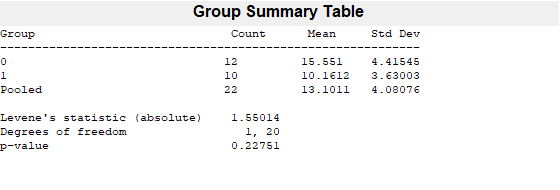

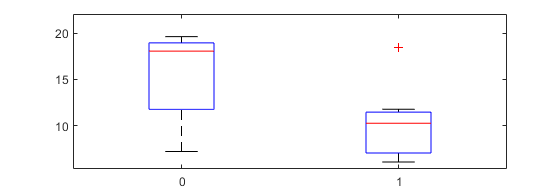

p = 0.2275

group_sol_small_dsrt = CP_sol_small_dsrt; %create matrix with dsrt + group for vartestn test
group_sol_small_dsrt(:,2) = 0;
group_sol_small_dsrt(13:22,1) = TD_sol_small_dsrt;
group_sol_small_dsrt(13:end,2) = 1;
p = vartestn(group_sol_small_dsrt(:,1),group_sol_small_dsrt(:,2),'TestType','LeveneAbsolute')

p = vartestn(group_sol_small_dsrt(:,1),group_sol_small_dsrt(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.4904

[p,h,stats] = ranksum(CP_sol_small_dsrt,TD_sol_small_dsrt) %Wilcoxon rank sum test

p = 0.0092

h = logical
   1


stats = struct with fields:
       zval: 2.6046
    ranksum: 178


median(CP_sol_small_dsrt)

ans = 18.0541

iqr(CP_sol_small_dsrt)

ans = 7.1727

median(TD_sol_small_dsrt)

ans = 10.2616

iqr(TD_sol_small_dsrt)

ans = 4.4261

### Small groups used for machine learning - DSRT MG

CP does not have normally distributed data. Groups are statistically different.

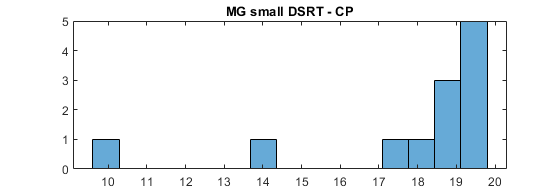

CP_mg_small_dsrt = rmmissing(Merged.median_fast_DSRT_MG(Merged.Group == "CP" & Merged.Subject ~= "5102" & Merged.Subject ~= "5116",:));
TD_mg_small_dsrt = rmmissing(Merged.median_fast_DSRT_MG(Merged.Group == "TD" & Merged.Subject ~= "5202" & Merged.Subject ~= "5208" ...
    & Merged.Subject ~= "5209" & Merged.Subject ~= "5217" & Merged.Subject ~= "5218",:)); 
histogram(CP_mg_small_dsrt,15),title('MG small DSRT - CP'),

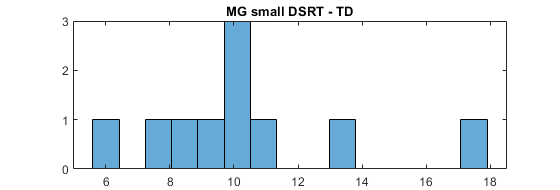

histogram(TD_mg_small_dsrt,15), title('MG small DSRT - TD'),

kurtosis_CP = kurtosis(CP_mg_small_dsrt)

kurtosis_CP = 5.5891

kurtosis_TD = kurtosis(TD_mg_small_dsrt)

kurtosis_TD = 3.9970

skewness_CP = skewness(CP_mg_small_dsrt)

skewness_CP = -1.9392

skewness_TD = skewness(TD_mg_small_dsrt)

skewness_TD = 1.1637

normalitytest(CP_mg_small_dsrt'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.1151 	     0.1662                 1 
KS Stephens Modification       1.1909 	     0.0100                 0 
KS Marsaglia Method            1.1151 	     0.1320                 1 
KS Lilliefors Modification     0.3219 	     0.0012                 0 
Anderson-Darling Test          1.6816 	     0.0006                 0 
Cramer- Von Mises Test         0.3045 	     0.0003                 0 
Shapiro-Wilk Test              0.6869 	     0.0006                 0 
Shapiro-Francia Test           0.6715 	     0.0007                 0 
Jarque-Bera Test               10.8725 	     0.0044                 0 
DAgostino & Pearson Test       16.4449 	     0.0003                 0 


normalitytest(TD_mg_small_dsrt');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8325 	     0.4922                 1 
KS Stephens Modification       0.9007 	     0.0486                 0 
KS Marsaglia Method            0.8325 	     0.4197                 1 
KS Lilliefors Modification     0.2633 	     0.0479                 0 
Anderson-Darling Test          0.5769 	     0.1340                 1 
Cramer- Von Mises Test         0.0952 	     0.1308                 1 
Shapiro-Wilk Test              0.8873 	     0.1609                 1 
Shapiro-Francia Test           0.8687 	     0.0855                 1 
Jarque-Bera Test               2.6714 	     0.2630                 1 
DAgostino & Pearson Test       7.0023 	     0.0302                 0 


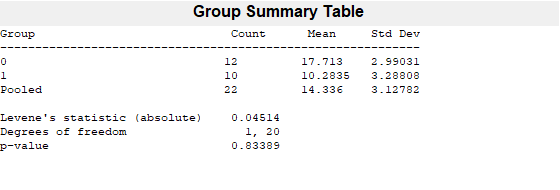

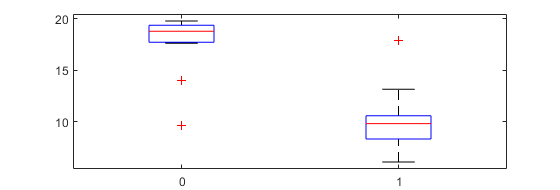

p = 0.8339

group_mg_small_dsrt = CP_mg_small_dsrt; %create matrix with dsrt + group for vartestn test
group_mg_small_dsrt(:,2) = 0;
group_mg_small_dsrt(13:22,1) = TD_mg_small_dsrt;
group_mg_small_dsrt(13:end,2) = 1;
p = vartestn(group_mg_small_dsrt(:,1),group_mg_small_dsrt(:,2),'TestType','LeveneAbsolute')

p = vartestn(group_mg_small_dsrt(:,1),group_mg_small_dsrt(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.8450

[p,h,stats] = ranksum(CP_mg_small_dsrt,TD_mg_small_dsrt) %Wilcoxon rank sum test

p = 8.6886e-04

h = logical
   1


stats = struct with fields:
       zval: 3.3299
    ranksum: 189


median(CP_mg_small_dsrt)

ans = 18.7978

iqr(CP_mg_small_dsrt)

ans = 1.6489

median(TD_mg_small_dsrt)

ans = 9.8170

iqr(TD_mg_small_dsrt)

ans = 2.2703

### Small groups used for machine learning - EMG SR burst Sol

Normal distribution, unequal variances. Groups are statistically different.

CP_sol_fastemg_small_burst = rmmissing(Merged.EMG_fast_normalized_sol(Merged.Group == "CP" & Merged.Subject ~= "5102" & Merged.Subject ~= "5116"));
TD_sol_fastemg_small_burst = Merged.EMG_fast_normalized_sol(Merged.Group == "TD" & Merged.Subject ~= "5202" ...
    & Merged.Subject ~= "5208" & Merged.Subject ~= "5209" & Merged.Subject ~= "5217" & Merged.Subject ~= "5218")

TD_sol_fastemg_small_burst =     0.0174
    0.1194
    0.0393
    0.0483
    0.0546
    0.0758
    0.1552
    0.2179
    0.1074
    0.0631


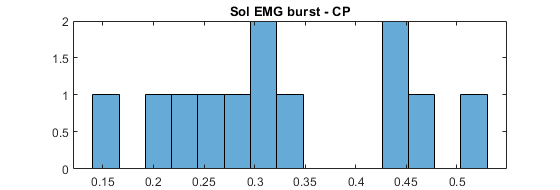

histogram(CP_sol_fastemg_small_burst,15),title('Sol EMG burst - CP'),

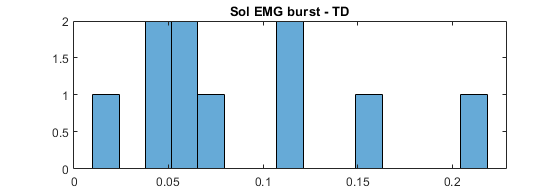

histogram(TD_sol_fastemg_small_burst,15), title('Sol EMG burst - TD'),

kurtosis_CP = kurtosis(CP_sol_fastemg_small_burst)

kurtosis_CP = 1.8889

kurtosis_TD = kurtosis(TD_sol_fastemg_small_burst)

kurtosis_TD = 2.9100

skewness_CP = skewness(CP_sol_fastemg_small_burst)

skewness_CP = 0.2260

skewness_TD = skewness(TD_sol_fastemg_small_burst)

skewness_TD = 0.9082

normalitytest(CP_sol_fastemg_small_burst'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6355 	     0.8140                 1 
KS Stephens Modification       0.6787 	     0.1500                 1 
KS Marsaglia Method            0.6355 	     0.7502                 1 
KS Lilliefors Modification     0.1835 	     0.2000                 1 
Anderson-Darling Test          0.3305 	     0.5137                 1 
Cramer- Von Mises Test         0.0567 	     0.4180                 1 
Shapiro-Wilk Test              0.9488 	     0.6192                 1 
Shapiro-Francia Test           0.9611 	     0.7101                 1 
Jarque-Bera Test               0.7195 	     0.6979                 1 
DAgostino & Pearson Test       1.0017 	     0.6060                 1 


normalitytest(TD_sol_fastemg_small_burst');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6031 	     0.8601                 1 
KS Stephens Modification       0.6525 	     0.1500                 1 
KS Marsaglia Method            0.6031 	     0.7958                 1 
KS Lilliefors Modification     0.1907 	     0.2000                 1 
Anderson-Darling Test          0.4165 	     0.3316                 1 
Cramer- Von Mises Test         0.0641 	     0.3344                 1 
Shapiro-Wilk Test              0.9174 	     0.3470                 1 
Shapiro-Francia Test           0.9148 	     0.2683                 1 
Jarque-Bera Test               1.3780 	     0.5021                 1 
DAgostino & Pearson Test       3.0843 	     0.2139                 1 


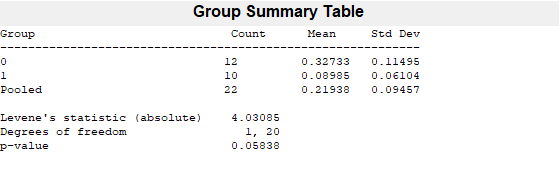

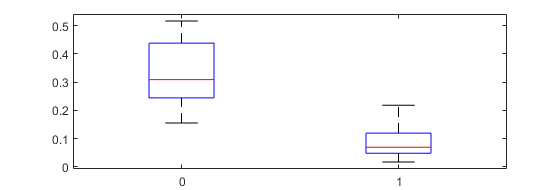

p = 0.0584

group_sol_small_emg = CP_sol_fastemg_small_burst; %create matrix with dsrt + group for vartestn test
group_sol_small_emg(:,2) = 0;
group_sol_small_emg(end+1:end+10,1) = TD_sol_fastemg_small_burst;
group_sol_small_emg(13:end,2) = 1;
p = vartestn(group_sol_small_emg(:,1),group_sol_small_emg(:,2),'TestType','LeveneAbsolute')

p = vartestn(group_sol_small_emg(:,1),group_sol_small_emg(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.0423

[h,p,ci,stats] = ttest2(CP_sol_fastemg_small_burst,TD_sol_fastemg_small_burst,'Vartype','unequal')

h = 1

p = 9.2466e-06

ci =     0.1566
    0.3184


stats = struct with fields:
    tstat: 6.1863
       df: 17.2841
       sd: [2×1 double]


### Small groups used for machine learning - EMG SR burst MG

Normal distribution, unequal variances. Groups are statistically different.

CP_mg_fastemg_small_burst = rmmissing(Merged.EMG_fast_normalized_mg(Merged.Group == "CP" & Merged.Subject ~= "5102" & Merged.Subject ~= "5116"));
TD_mg_fastemg_small_burst = Merged.EMG_fast_normalized_mg(Merged.Group == "TD" & Merged.Subject ~= "5202" ...
    & Merged.Subject ~= "5208" & Merged.Subject ~= "5209" & Merged.Subject ~= "5217" & Merged.Subject ~= "5218")

TD_mg_fastemg_small_burst =     0.0044
    0.0291
    0.0060
    0.0191
    0.0367
    0.0511
    0.0984
    0.0834
    0.0250
    0.0148


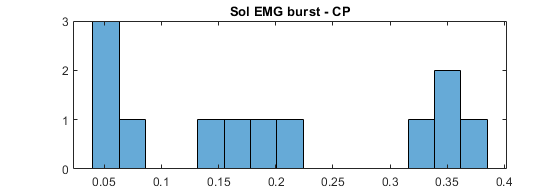

histogram(CP_mg_fastemg_small_burst,15),title('Sol EMG burst - CP'),

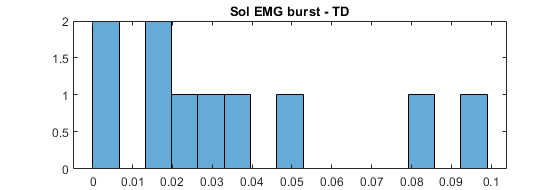

histogram(TD_mg_fastemg_small_burst,15), title('Sol EMG burst - TD'),

kurtosis_CP = kurtosis(CP_mg_fastemg_small_burst)

kurtosis_CP = 1.4987

kurtosis_TD = kurtosis(TD_mg_fastemg_small_burst)

kurtosis_TD = 2.5610

skewness_CP = skewness(CP_mg_fastemg_small_burst)

skewness_CP = 0.2304

skewness_TD = skewness(TD_mg_fastemg_small_burst)

skewness_TD = 0.9239

normalitytest(CP_mg_fastemg_small_burst'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5965 	     0.8688                 1 
KS Stephens Modification       0.6371 	     0.1500                 1 
KS Marsaglia Method            0.5965 	     0.8118                 1 
KS Lilliefors Modification     0.1722 	     0.2000                 1 
Anderson-Darling Test          0.6004 	     0.0710                 1 
Cramer- Von Mises Test         0.0791 	     0.2132                 1 
Shapiro-Wilk Test              0.8713 	     0.0679                 1 
Shapiro-Francia Test           0.9011 	     0.1410                 1 
Jarque-Bera Test               1.2330 	     0.5398                 1 
DAgostino & Pearson Test       3.8628 	     0.1449                 1 


normalitytest(TD_mg_fastemg_small_burst');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6343 	     0.8159                 1 
KS Stephens Modification       0.6862 	     0.1500                 1 
KS Marsaglia Method            0.6343 	     0.7458                 1 
KS Lilliefors Modification     0.2006 	     0.2000                 1 
Anderson-Darling Test          0.5897 	     0.1243                 1 
Cramer- Von Mises Test         0.0932 	     0.1397                 1 
Shapiro-Wilk Test              0.8738 	     0.1134                 1 
Shapiro-Francia Test           0.8826 	     0.1203                 1 
Jarque-Bera Test               1.5029 	     0.4717                 1 
DAgostino & Pearson Test       2.6915 	     0.2603                 1 


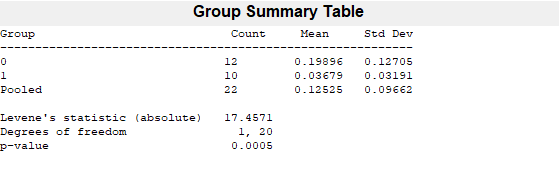

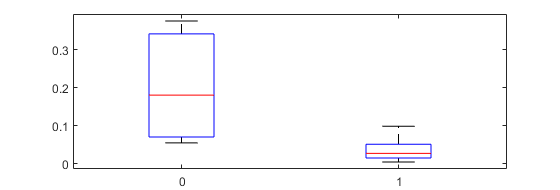

p = 4.6379e-04

group_mg_small_emg = CP_mg_fastemg_small_burst; %create matrix with dsrt + group for vartestn test
group_mg_small_emg(:,2) = 0;
group_mg_small_emg(end+1:end+10,1) = TD_mg_fastemg_small_burst;
group_mg_small_emg(13:end,2) = 1;
p = vartestn(group_mg_small_emg(:,1),group_mg_small_emg(:,2),'TestType','LeveneAbsolute')

p = vartestn(group_mg_small_emg(:,1),group_mg_small_emg(:,2),'TestType','LeveneQuadratic','display','off')

p = 7.2840e-04

[h,p,ci,stats] = ttest2(CP_mg_fastemg_small_burst,TD_mg_fastemg_small_burst,'Vartype','unequal')

h = 1

p = 9.8245e-04

ci =     0.0798
    0.2446


stats = struct with fields:
    tstat: 4.2633
       df: 12.6399
       sd: [2×1 double]


### Correlation between output variables - DSRT vs. SR EMG response

Linear relationship between median values of DSRT and SR EMG response (normalized by MVC) in CP for both muscles.

normalitytest(rmmissing(Merged.median_DSRT_Sol_Lat(Merged.Group == "CP")'))

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.0413 	     0.2283                 1 
KS Stephens Modification       1.1065 	     0.0100                 0 
KS Marsaglia Method            1.0413 	     0.1872                 1 
KS Lilliefors Modification     0.2888 	     0.0040                 0 
Anderson-Darling Test          1.1883 	     0.0054                 0 
Cramer- Von Mises Test         0.2125 	     0.0038                 0 
Shapiro-Wilk Test              0.8073 	     0.0083                 0 
Shapiro-Francia Test           0.8193 	     0.0130                 0 
Jarque-Bera Test               2.0234 	     0.3636                 1 
DAgostino & Pearson Test       2.8025 	     0.2463                 1 


ans =     1.0413    0.2283    1.0000
    1.1065    0.0100         0
    1.0413    0.1872    1.0000
    0.2888    0.0040         0
    1.1883    0.0054         0
    0.2125    0.0038         0
    0.8073    0.0083         0
    0.8193    0.0130         0
    2.0234    0.3636    1.0000
    2.8025    0.2463    1.0000


normalitytest(rmmissing(Merged.EMG_normalized_sol(Merged.Group == "CP")'))

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8551 	     0.4576                 1 
KS Stephens Modification       0.9086 	     0.0466                 0 
KS Marsaglia Method            0.8551 	     0.3955                 1 
KS Lilliefors Modification     0.2372 	     0.0440                 0 
Anderson-Darling Test          0.9598 	     0.0147                 0 
Cramer- Von Mises Test         0.1537 	     0.0213                 0 
Shapiro-Wilk Test              0.8152 	     0.0104                 0 
Shapiro-Francia Test           0.8058 	     0.0093                 0 
Jarque-Bera Test               6.2232 	     0.0445                 0 
DAgostino & Pearson Test       10.7808 	     0.0046                 0 


ans =     0.8551    0.4576    1.0000
    0.9086    0.0466         0
    0.8551    0.3955    1.0000
    0.2372    0.0440         0
    0.9598    0.0147         0
    0.1537    0.0213         0
    0.8152    0.0104         0
    0.8058    0.0093         0
    6.2232    0.0445         0
   10.7808    0.0046         0


scatter(Merged.median_DSRT_Sol_Lat(Merged.Group == "CP"),Merged.EMG_normalized_sol(Merged.Group == "CP"),'rx')
hold on
title("Sol SR EMG vs. DSRT"), ylabel("SR EMG response"), xlabel("DSRT"), legend('CP', 'TD')

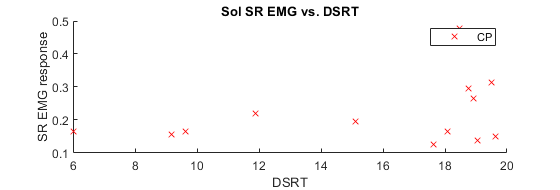

hold off

[rho,pval] = corr(Merged.median_DSRT_Sol_Lat(Merged.Group == "CP"),Merged.EMG_normalized_sol(Merged.Group == "CP") , 'rows', "pairwise",'type',"Spearman")

rho = 0.1813

pval = 0.5533

scatter(Merged.median_DSRT_MG_Lat(Merged.Group == "CP"),Merged.EMG_normalized_mg(Merged.Group == "CP"),'rx' )
hold on
title("MG SR EMG vs. DSRT"), ylabel("SR EMG response"), xlabel("DSRT"), legend('CP', 'TD')

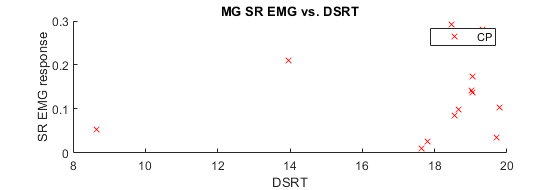

hold off

normalitytest(rmmissing(Merged.median_DSRT_MG_Lat(Merged.Group == "CP")'))

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.2354 	     0.0945                 1 
KS Stephens Modification       1.3128 	     0.0100                 0 
KS Marsaglia Method            1.2354 	     0.0725                 1 
KS Lilliefors Modification     0.3426 	     0.0002                 0 
Anderson-Darling Test          2.0430 	     0.0001                 0 
Cramer- Von Mises Test         0.3770 	     0.0000                 0 
Shapiro-Wilk Test              0.6450 	     0.0002                 0 
Shapiro-Francia Test           0.6242 	     0.0002                 0 
Jarque-Bera Test               18.3367 	     0.0001                 0 
DAgostino & Pearson Test       21.1825 	     0.0000                 0 


ans =     1.2354    0.0945    1.0000
    1.3128    0.0100         0
    1.2354    0.0725    1.0000
    0.3426    0.0002         0
    2.0430    0.0001         0
    0.3770    0.0000         0
    0.6450    0.0002         0
    0.6242    0.0002         0
   18.3367    0.0001         0
   21.1825    0.0000         0


normalitytest(rmmissing(Merged.EMG_normalized_mg(Merged.Group == "CP")'))

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4931 	     0.9682                 1 
KS Stephens Modification       0.5240 	     0.1500                 1 
KS Marsaglia Method            0.4931 	     0.9410                 1 
KS Lilliefors Modification     0.1368 	     0.2000                 1 
Anderson-Darling Test          0.3491 	     0.4752                 1 
Cramer- Von Mises Test         0.0450 	     0.5904                 1 
Shapiro-Wilk Test              0.9293 	     0.3339                 1 
Shapiro-Francia Test           0.9440 	     0.4326                 1 
Jarque-Bera Test               1.0118 	     0.6030                 1 
DAgostino & Pearson Test       1.2496 	     0.5354                 1 


ans =     0.4931    0.9682    1.0000
    0.5240    0.1500    1.0000
    0.4931    0.9410    1.0000
    0.1368    0.2000    1.0000
    0.3491    0.4752    1.0000
    0.0450    0.5904    1.0000
    0.9293    0.3339    1.0000
    0.9440    0.4326    1.0000
    1.0118    0.6030    1.0000
    1.2496    0.5354    1.0000


[rho_cp_mg,pval_cp_mg] = corr(Merged.median_DSRT_MG_Lat(Merged.Group == "CP"),Merged.EMG_normalized_mg(Merged.Group == "CP") , 'rows', "pairwise",'type',"Spearman")

rho_cp_mg = 0.2198

pval_cp_mg = 0.4706